# Behaviour: Elaborated analysis

## 0. Load data

%load Data and exclusion files
load(fullfile('..','data','data_struct.mat'));
subjects = subjects(relevant_ss);
%the excludeSubjects scrips works block-wise. To convert to a trial-wise inclusion list, 
%replicate each entry 40 times. 
included_trials = rectpulse((toExclude'==0&toExcludeFromConfAnalyses'==0)+0,40)';

%add nice things to path
load('cb.mat')

% addpath('D:\Documents\software\raincloud_plots') %for rainclouds
% addpath('D:\Documents\software\mseb'); %for nice shaded errors
lineProps.width=1; lineProps.col = {cb(1,:), cb(4,:)};
linePropsDiff.width=1; linePropsDiff.col = {'k'}; linePropsDiff.style = '-';


## 1. Reaction times for the four responses

only taking into account trials that ended up in the fMRI analysis.

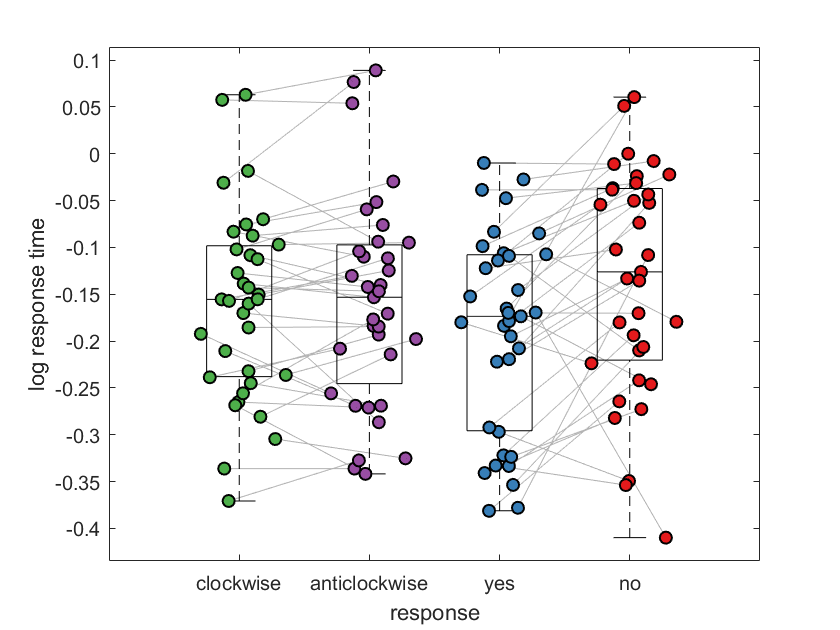

Error using hgexport
Error using matlab.graphics.internal.name (line 101)
Cannot create output file 'figures\RTxResponse.png'.

meanRT_C = [];
meanRT_A = [];
meanRT_Y = [];
meanRT_N = [];
meanRT_correct = [];
meanRT_incorrect = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    RT_C = log(subject.DisRT(subject.DisResp==1 & included_trials(s,:)'));
    RT_A = log(subject.DisRT(subject.DisResp==0 & included_trials(s,:)'));
    RT_Y = log(subject.DetRT(subject.DetResp==1 & included_trials(s,:)'));
    RT_N = log(subject.DetRT(subject.DetResp==0 & included_trials(s,:)'));
    RT_correct = log([subject.DetRT(subject.DetCorrect ==1 & included_trials(s,:)'); ...
        subject.DisRT(subject.DisCorrect ==1 & included_trials(s,:)')]);
    RT_incorrect = log([subject.DetRT(subject.DetCorrect ==0 & included_trials(s,:)'); ...
        subject.DisRT(subject.DisCorrect ==0 & included_trials(s,:)')]);
    
    meanRT_C(s) = nanmean(RT_C);
    meanRT_A(s) = nanmean(RT_A);
    meanRT_Y(s) = nanmean(RT_Y);
    meanRT_N(s) = nanmean(RT_N);
    meanRT_correct(s) = nanmean(RT_correct);
    meanRT_incorrect(s) = nanmean(RT_incorrect);

    
end

figure; hold on;
noise = normrnd(0,0.1,35,1);
plot([ones(35,1)+noise 2*ones(35,1)+noise]', [meanRT_C' meanRT_A']','Color',[0.7,0.7,0.7]);
plot([3*ones(35,1)+noise 4*ones(35,1)+noise]', [meanRT_Y' meanRT_N']','Color',[0.7,0.7,0.7]);
boxplot([meanRT_C; meanRT_A; meanRT_Y; meanRT_N]','Colors','k');
scatter(ones(35,1)+noise,meanRT_C,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(2*ones(35,1)+noise,meanRT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(3*ones(35,1)+noise,meanRT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(35,1)+noise,meanRT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('log response time');
xlim([0,5]); xlabel('response');
set(gca,'xtick',[1:4],'xticklabel',{'clockwise','anticlockwise','yes','no'})

fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 20;
s.Height = 10;
% hgexport(fig,'figures/RTxResponse',s);

## 2. Accuracy

Contrasting mean accuracy and d' for the two tasks.

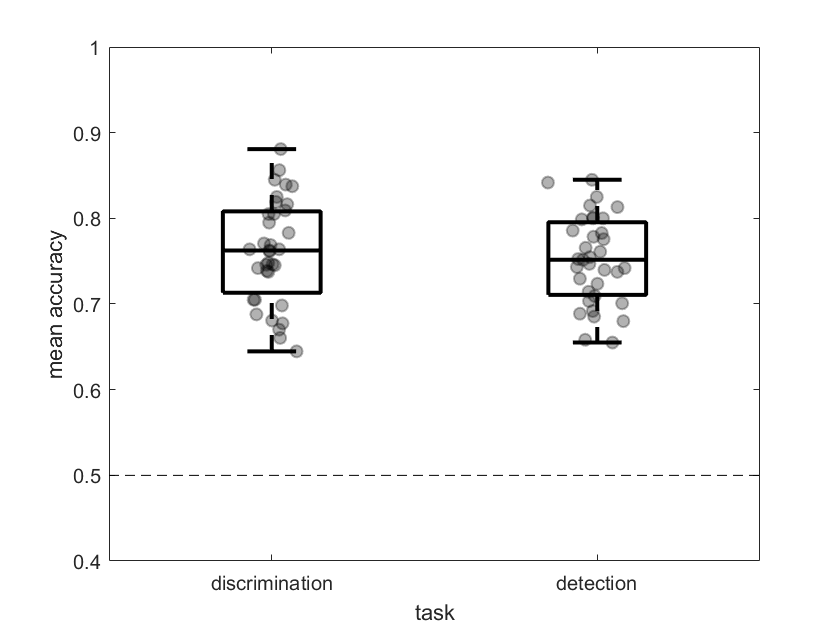

meanAccDet = [];
meanAccDis = [];
mean_dprimeDet = [];
mean_dprimeDis = [];
meanAUROCDet = [];
meanAUROCDis = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    
    AccDet = subject.DetCorrect(find(included_trials(s,:)));
    AccDis = subject.DisCorrect(find(included_trials(s,:)));
    
    dprimeDet = norminv(nanmean(subject.DetResp(subject.DetSignal == 1 & included_trials(s,:)'))) - ...
        norminv(nanmean(subject.DetResp(subject.DetSignal == 0 & included_trials(s,:)')));
    
    dprimeDis = norminv(nanmean(subject.DisResp(subject.DisSignal == 1 & included_trials(s,:)'))) - ...
        norminv(nanmean(subject.DisResp(subject.DisSignal == 0 & included_trials(s,:)')));
    
    AUROCDet = extractAUROC(subject.DetSignal,subject.DetResp,subject.DetConf);
    
    AUROCDis = extractAUROC(subject.DisSignal,subject.DisResp,subject.DisConf);
    
    meanAccDet(s) = nanmean(AccDet);
    meanAccDis(s) = nanmean(AccDis);

    mean_dprimeDet(s) = dprimeDet;
    mean_dprimeDis(s) = dprimeDis;
    
    meanAUROCDet(s) = AUROCDet;
    meanAUROCDis(s) = AUROCDis;

end
noise1 = normrnd(0,0.05,1,35);
noise2 = normrnd(0,0.05,1,35);
figure; hold on;
h=boxplot([meanAccDis;meanAccDet]','Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(ones(35,1)+noise1',meanAccDis,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(35,1)+noise2',meanAccDet,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean accuracy');
xlim([0.5,2.5]); xlabel('task');
ylim([0.4,1]);
plot([0.5,2.5],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'discrimination','detection'})

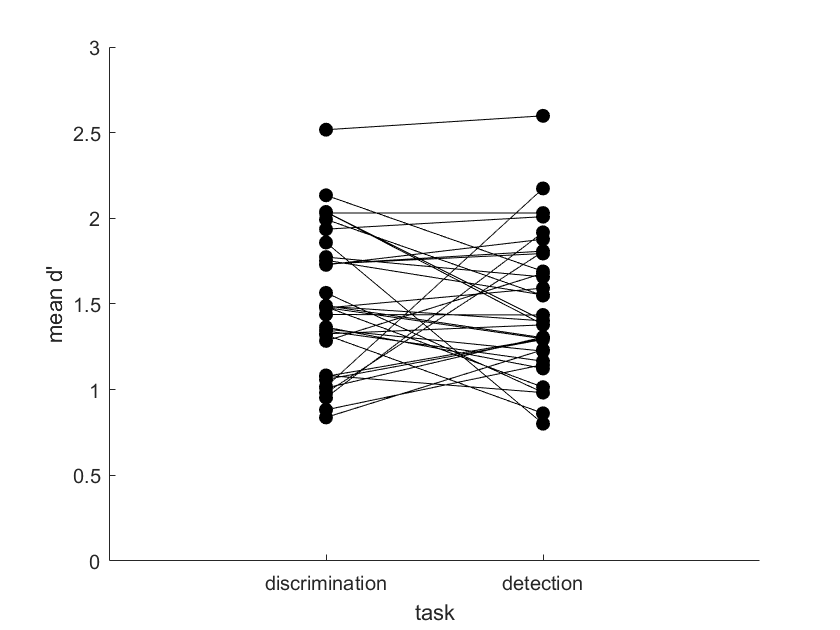

fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 20;
s.Height = 10;
% hgexport(fig,'figures/accuracy',s);

figure; hold on;
plot([mean_dprimeDis;mean_dprimeDet],'k');
scatter(ones(35,1),mean_dprimeDis,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
scatter(2*ones(35,1),mean_dprimeDet,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
ylabel('mean d'''); ylim([0,3]);
xlim([0,3]); xlabel('task');
set(gca,'xtick',[1:2],'xticklabel',{'discrimination','detection'})

## 2.1 Correlation between response times, accuracy, and confidence

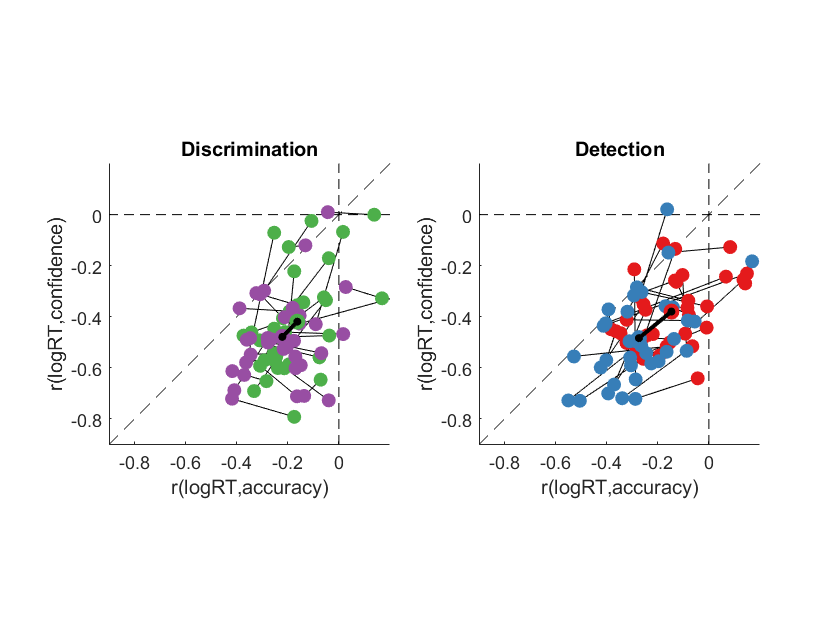

[RTxconf,RTxacc,accxconf] = deal(nan(10,5));

for s=1:length(subjects)

    subject = data_struct(subjects{s});
    
    yesConf = subject.DetConf(subject.DetResp==1 & included_trials(s,:)');
    yesRT = log(subject.DetRT(subject.DetResp==1 & included_trials(s,:)'));
    yesAcc = subject.DetCorrect(subject.DetResp==1 & included_trials(s,:)');
    corryes = corr([yesConf yesRT yesAcc], 'Type','Spearman');
    
    noConf = subject.DetConf(subject.DetResp==0 & included_trials(s,:)');
    noRT = log(subject.DetRT(subject.DetResp==0 & included_trials(s,:)'));
    noAcc = subject.DetCorrect(subject.DetResp==0 & included_trials(s,:)');
    corrno = corr([noConf noRT noAcc], 'Type','Spearman');
    
    upConf = subject.DisConf(subject.DisResp==1 & included_trials(s,:)');
    upRT = log(subject.DisRT(subject.DisResp==1 & included_trials(s,:)'));
    upAcc = subject.DisCorrect(subject.DisResp==1 & included_trials(s,:)');
    corrup = corr([upConf upRT upAcc], 'Type','Spearman');
    
    downConf = subject.DisConf(subject.DisResp==0 & included_trials(s,:)');
    downRT = log(subject.DisRT(subject.DisResp==0 & included_trials(s,:)'));
    downAcc = subject.DisCorrect(subject.DisResp==0 & included_trials(s,:)');
    corrdown = corr([downConf downRT downAcc], 'Type','Spearman');
    
    corrgeneral = corr([[subject.DisConf; subject.DetConf],...
        log([subject.DisRT; subject.DetRT]),...
        [subject.DisCorrect; subject.DetCorrect]], 'Type','Spearman');
    
    RTxconf(s,:) = ([ corrup(2,1) corrdown(2,1) corryes(2,1) corrno(2,1) corrgeneral(2,1)]);
    RTxacc(s,:) = ([ corrup(2,3) corrdown(2,3) corryes(2,3) corrno(2,3) corrgeneral(2,3)]);
    accxconf(s,:) = ([ corrup(3,1) corrdown(3,1) corryes(3,1) corrno(3,1) corrgeneral(3,1)]);
end

figure; subplot(1,2,2); hold on;
axis equal
plot([-1,1; -1 1; 0 0]',[-1,1; 0 0 ; -1 1]','--k'); 
xlabel('r(logRT,accuracy)');
ylabel('r(logRT,confidence)');
xticks(-0.6:0.2:0); yticks(-0.6:0.2:0);
plot([RTxacc(:,4)  RTxacc(:,3) ]',[RTxconf(:,4) RTxconf(:,3) ]','k')

set(gca,'xtick',-0.8:0.2:0); xlim([-0.9,0.2]);
set(gca,'ytick',-0.8:0.2:0); ylim([-0.9,0.2]);
scatter(RTxacc(:,4),RTxconf(:,4),[],'MarkerEdgeColor',cb(1,:),'MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(RTxacc(:,3),RTxconf(:,3),[],'MarkerEdgeColor',cb(2,:),'MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(mean(RTxacc(:,4)),mean(RTxconf(:,4)),[],'MarkerEdgeColor',cb(1,:),'MarkerFaceColor','k','LineWidth',2);
scatter(mean(RTxacc(:,3)),mean(RTxconf(:,3)),[],'MarkerEdgeColor',cb(2,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,4)), mean(RTxacc(:,3))],[mean(RTxconf(:,4)), mean(RTxconf(:,3))],'k','LineWidth',2);
title('Detection');

subplot(1,2,1); hold on;
axis equal
xlabel('r(logRT,accuracy)');
ylabel('r(logRT,confidence)');
plot([RTxacc(:,1)  RTxacc(:,2) ]',[RTxconf(:,1) RTxconf(:,2) ]','k')
plot([-1,1; -1 1; 0 0]',[-1,1; 0 0 ; -1 1]','--k'); 
set(gca,'xtick',-0.8:0.2:0); xlim([-0.9,0.2]);
set(gca,'ytick',-0.8:0.2:0); ylim([-0.9,0.2]);
scatter(RTxacc(:,1),RTxconf(:,1),[],'MarkerEdgeColor',cb(3,:),'MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(RTxacc(:,2),RTxconf(:,2),[],'MarkerEdgeColor',cb(4,:),'MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(mean(RTxacc(:,1)),mean(RTxconf(:,1)),[],'MarkerEdgeColor',cb(3,:),'MarkerFaceColor','k','LineWidth',2);
scatter(mean(RTxacc(:,2)),mean(RTxconf(:,2)),[],'MarkerEdgeColor',cb(4,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,1)), mean(RTxacc(:,2))],[mean(RTxconf(:,1)), mean(RTxconf(:,2))],'k','LineWidth',2);
title('Discrimination');

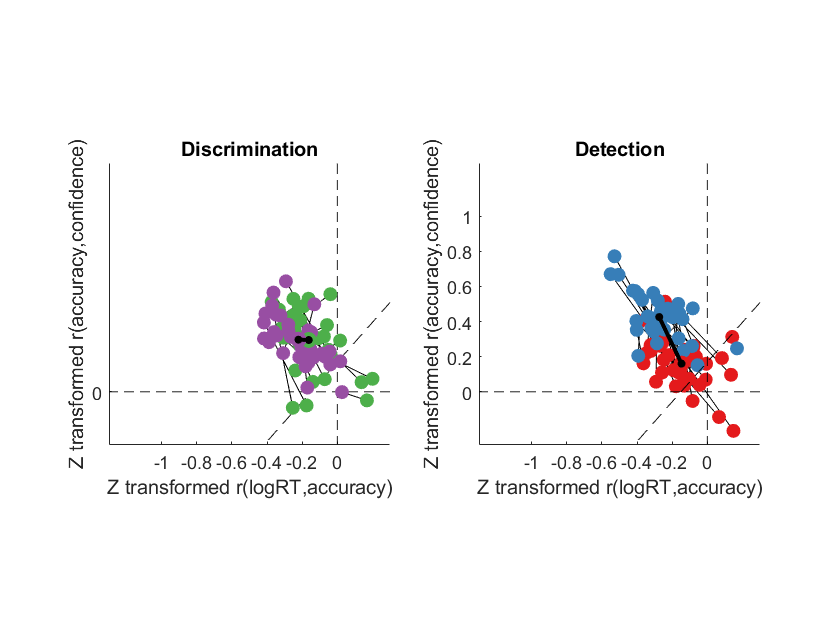




figure; subplot(1,2,2); hold on;
axis equal
xlabel('Z transformed r(logRT,accuracy)');
ylabel('Z transformed r(accuracy,confidence)');
plot([RTxacc(:,4)  RTxacc(:,3) ]',[accxconf(:,4) accxconf(:,3) ]','k')

set(gca,'xtick',-1:0.2:0); xlim([-1.3,0.3]);
set(gca,'ytick',0:0.2:1); ylim([-0.3,1.3]);
scatter(RTxacc(:,4),accxconf(:,4),[],'MarkerEdgeColor',cb(1,:),'MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(RTxacc(:,3),accxconf(:,3),[],'MarkerEdgeColor',cb(2,:),'MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(mean(RTxacc(:,4)),mean(accxconf(:,4)),[],'MarkerEdgeColor',cb(1,:),'MarkerFaceColor','k','LineWidth',2);
scatter(mean(RTxacc(:,3)),mean(accxconf(:,3)),[],'MarkerEdgeColor',cb(2,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,4)), mean(RTxacc(:,3))],[mean(accxconf(:,4)), mean(accxconf(:,3))],'k','LineWidth',2);
plot([-1.3,1; -1.3 1.3; 0 0]',[-1.3,1.3; 0 0 ; -1.3 1.3]','--k'); 
title('Detection');

subplot(1,2,1); hold on;
axis equal
xlabel('Z transformed r(logRT,accuracy)');
ylabel('Z transformed r(accuracy,confidence)');
plot([RTxacc(:,1)  RTxacc(:,2) ]',[accxconf(:,1) accxconf(:,2) ]','k')
plot([-1.3,1; -1.3 1.3; 0 0]',[-1.3,1.3; 0 0 ; -1.3 1.3]','--k'); 
set(gca,'xtick',-1:0.2:0); xlim([-1.3,0.3]);
set(gca,'ytick',0:0.2:0); ylim([-0.3,1.3]);
scatter(RTxacc(:,1),accxconf(:,1),[],'MarkerEdgeColor',cb(3,:),'MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(RTxacc(:,2),accxconf(:,2),[],'MarkerEdgeColor',cb(4,:),'MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(mean(RTxacc(:,1)),mean(accxconf(:,1)),[],'MarkerEdgeColor',cb(3,:),'MarkerFaceColor','k','LineWidth',2);
scatter(mean(RTxacc(:,2)),mean(accxconf(:,2)),[],'MarkerEdgeColor',cb(4,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,1)), mean(RTxacc(:,2))],[mean(accxconf(:,1)), mean(accxconf(:,2))],'k','LineWidth',2);
title('Discrimination');

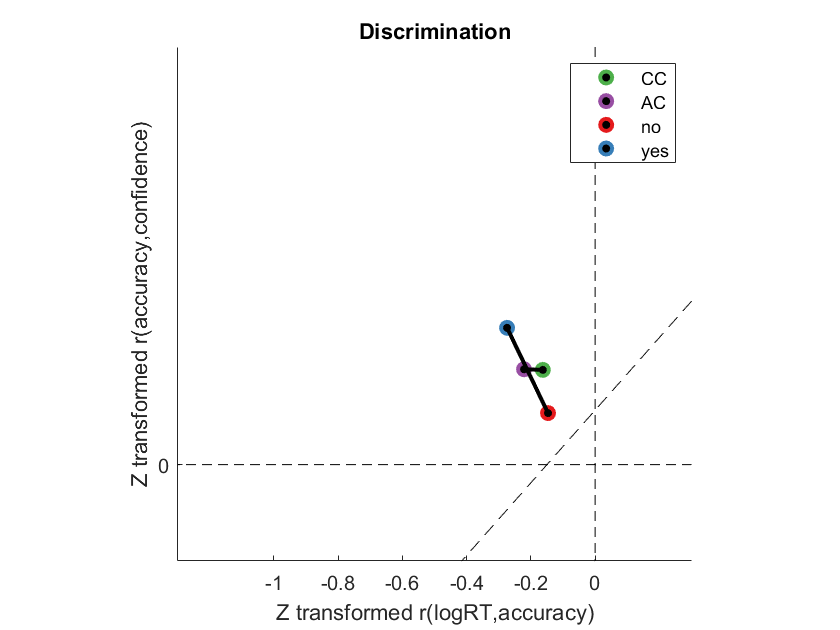


figure; hold on; axis equal
xlabel('Z transformed r(logRT,accuracy)');
ylabel('Z transformed r(accuracy,confidence)');
plot([-1.3,1; -1.3 1.3; 0 0]',[-1.3,1.3; 0 0 ; -1.3 1.3]','--k'); 
set(gca,'xtick',-1:0.2:0); xlim([-1.3,0.3]);
set(gca,'ytick',0:0.2:0); ylim([-0.3,1.3]);
up=scatter(mean(RTxacc(:,1)),mean(accxconf(:,1)),[],'MarkerEdgeColor',cb(3,:),'MarkerFaceColor','k','LineWidth',2);
down=scatter(mean(RTxacc(:,2)),mean(accxconf(:,2)),[],'MarkerEdgeColor',cb(4,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,1)), mean(RTxacc(:,2))],[mean(accxconf(:,1)), mean(accxconf(:,2))],'k','LineWidth',2);
no=scatter(mean(RTxacc(:,4)),mean(accxconf(:,4)),[],'MarkerEdgeColor',cb(1,:),'MarkerFaceColor','k','LineWidth',2);
yes=scatter(mean(RTxacc(:,3)),mean(accxconf(:,3)),[],'MarkerEdgeColor',cb(2,:),'MarkerFaceColor','k','LineWidth',2);
plot([mean(RTxacc(:,4)), mean(RTxacc(:,3))],[mean(accxconf(:,4)), mean(accxconf(:,3))],'k','LineWidth',2);
title('Discrimination');
legend([up,down,no,yes],{'CC','AC','no','yes'})

## 3. Serial correlations

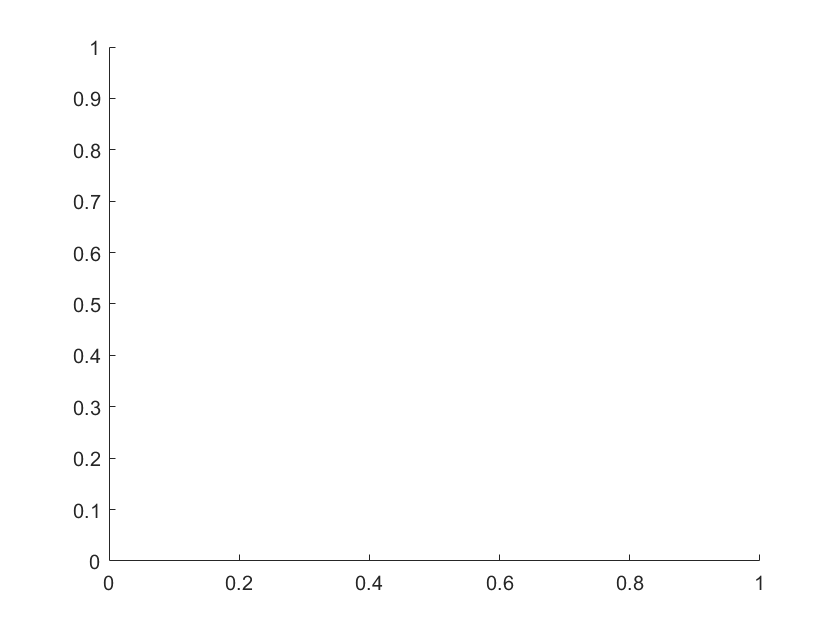

Dis_Coeffs = [];
Det_Coeffs = [];

Dis_corr = [];
Det_corr = [];

for s=1:length(subjects) %run over subjects
    
    subject = data_struct(subjects{s});
    
    DisMat = [];
    DetMat = [];
    
    DisSigMat = [];
    DetSigMat = [];
    
    for i = 1:8 %lags 
        
        DisVec = []; %responses for discrimination
        DetVec = []; %responses for detection
        
        DisSig = []; %signal for discrimination
        DetSig = []; %signal for detection
        
        for block = 1:5
            
            if toExclude(s,block)==0
                
                % add 32 responses from each block
                DisVec = [DisVec; subject.DisResp(i+(block-1)*40:i+(block-1)*40+32)];
                DetVec = [DetVec; subject.DetResp(i+(block-1)*40:i+(block-1)*40+32)];
                
                % add the appropriate 32 signals 
                DisSig = [DisSig; subject.DisSignal(i+(block-1)*40:i+(block-1)*40+32)];
                DetSig = [DetSig; subject.DetSignal(i+(block-1)*40:i+(block-1)*40+32)];
                
            end
        end
        
        DisMat = [DisMat DisVec]; % each lag value gets one column in the matrix
        DetMat = [DetMat DetVec];
        
        DisSigMat = [DisSigMat DisSig]; % same for signals
        DetSigMat = [DetSigMat DetSig];
       
    end
    
    toPredictDis = DisMat(:,8); % what I want to predict is the last column in the response matrix
    toPredictDis(toPredictDis==0)=2; %the second category is used as reference by mnrfit
    regressorsDis = [DisMat(:,7:-1:1), DisSigMat(:,8)]; % responses in reverse lag order, then signals
    Dis_B = mnrfit(regressorsDis, toPredictDis); %fit a logistic regression model
    
    toPredictDet = DetMat(:,8);
    toPredictDet(toPredictDet==0)=2; %the second category is used as reference by mnrfit
    regressorsDet = [DetMat(:,7:-1:1), DetSigMat(:,8)]; % responses in reverse lag order, then signals
    Det_B = mnrfit(regressorsDet, toPredictDet); %fit a logistic regression model   
    
    Dis_Coeffs = [Dis_Coeffs Dis_B(2:8)]; % add the first 7 slope betas
    Det_Coeffs = [Det_Coeffs Det_B(2:8)]; % add the first 7 slope betas
    
    Dis_corr = cat(3, Dis_corr, corr(DisMat(~any(isnan(DisMat),2),:))); %compute correlations
    Det_corr = cat(3, Det_corr,corr(DetMat(~any(isnan(DetMat),2),:)));  %compute correlations
    
end

    Dis_corr_vec = squeeze(Dis_corr(5:-1:1,6,:))';
    Det_corr_vec = squeeze(Det_corr(5:-1:1,6,:))';
    
   %MUST HAVE THE MSEB PACKAGE TO PRODUCE THESE FIGURES:
   %https://uk.mathworks.com/matlabcentral/fileexchange/47950-mseb-x-y-errbar-lineprops-transparent

%     figure
%     hold on

%     mseb(1:5, [mean(Dis_corr_vec);mean(Det_corr_vec)] ,...
%         [std(Dis_corr_vec); std(Det_corr_vec)]/sqrt(length(subjects))*2, lineProps);

Undefined function or variable 'mseb'.

%     legend('discrimination','detection')
%     plot([1,5],[0,0],'--k');
%     xlabel('lag');
%     ylabel('correlation')
%     
%     figure
%     hold on
%     mseb(1:7, [mean(Dis_Coeffs');mean(Det_Coeffs')] ,...
%         [std(Dis_Coeffs'); std(Det_Coeffs')]/sqrt(length(subjects)), lineProps);
%     legend('discrimination','detection')
%     plot([1,7],[0,0],'--k');
%     xlabel('lag');
%     ylabel('weight')
    % check overall difference in dependency temporal window:
    Dis_window = [];
    Det_window = [];
    Dis_height = [];
    Det_height = [];
    for s = 1:length(subjects)
        Dis_window(s) = find([Dis_Coeffs(:,s); 0]<=0,1);
        Det_window(s) = find([Det_Coeffs(:,s); 0]<=0,1);
        Dis_height(s) = mean(Dis_Coeffs(1:Dis_window(s)-1,s));
        Det_height(s) = mean(Det_Coeffs(1:Dis_window(s)-1,s));

    end

## 3.1 Alternating and sustained effects of previous trials

alternating_regressor = [-1 1 -1 1 -1 1 -1];
sustained_regressor = 3:-1:-3;
predictors = [ones(7,1), alternating_regressor', sustained_regressor'];
trends_dis = [];
trends_det = [];

for i_s = 1:length(subjects);
    trends_dis(:, i_s) = regress(Dis_Coeffs(:,i_s), predictors);
    trends_det(:, i_s) = regress(Det_Coeffs(:,i_s), predictors);
end

There is no significant difference in the contribution of sustained and alternating effects on the two tasks (though it might seem this way from the group plot).

## 4. Association between RT and confidence

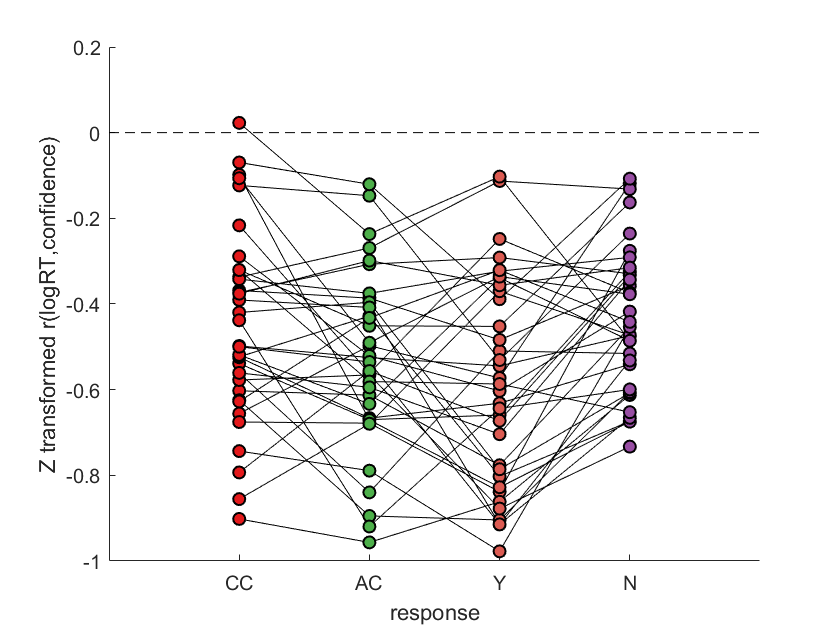

cor_C = [];
cor_A = [];
cor_Y = [];
cor_N = [];

RTmat_C = nan(length(subjects),6);
RTmat_A = nan(length(subjects),6);
RTmat_Y = nan(length(subjects),6);
RTmat_N = nan(length(subjects),6);



for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    RT_C = subject.DisRT(subject.DisResp==1 & included_trials(s,:)');
    RT_A = subject.DisRT(subject.DisResp==0 & included_trials(s,:)');
    RT_Y = subject.DetRT(subject.DetResp==1 & included_trials(s,:)');
    RT_N = subject.DetRT(subject.DetResp==0 & included_trials(s,:)');
    
    conf_C = subject.DisConf(subject.DisResp==1 & included_trials(s,:)');
    conf_A = subject.DisConf(subject.DisResp==0 & included_trials(s,:)');
    conf_Y = subject.DetConf(subject.DetResp==1 & included_trials(s,:)');
    conf_N = subject.DetConf(subject.DetResp==0 & included_trials(s,:)');
    
    cor_C(s) = atanh(corr(conf_C, log(RT_C)));
    cor_A(s) = atanh(corr(conf_A, log(RT_A)));
    cor_Y(s) = atanh(corr(conf_Y, log(RT_Y)));
    cor_N(s) = atanh(corr(conf_N, log(RT_N)));
    
    for i_r = 1:6
       RTmat_C(s,i_r) = mean(RT_C(conf_C==i_r));
       RTmat_A(s,i_r) = mean(RT_A(conf_A==i_r));
       RTmat_Y(s,i_r) = mean(RT_Y(conf_Y==i_r));
       RTmat_N(s,i_r) = mean(RT_N(conf_N==i_r));
    end
    
    
end

figure; hold on;
plot([cor_C;cor_A;cor_Y;cor_N],'k');
scatter(ones(35,1),cor_C,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(2*ones(35,1),cor_A,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(3*ones(35,1),cor_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(5,:),'LineWidth',1);
scatter(4*ones(35,1),cor_N,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
ylabel('Z transformed r(logRT,confidence)');
xlim([0,5]); xlabel('response');
set(gca,'xtick',[1:4],'xticklabel',{'CC','AC','Y','N'})
plot([0,5],[0,0],'--k');

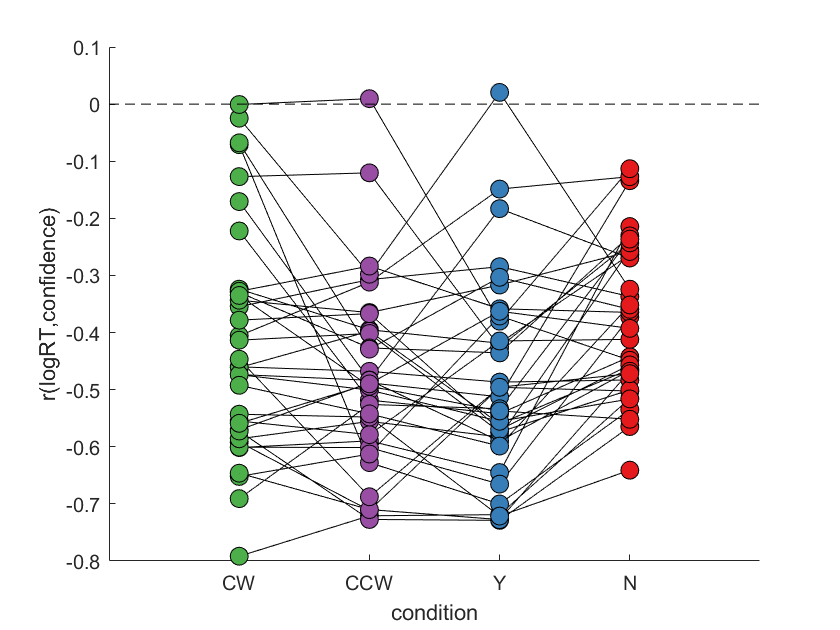

Error using hgexport
Error using matlab.graphics.internal.name (line 101)
Cannot create output file 'figures\rRTConfxResponse.png'.

[RTxconf,RTxacc,accxconf] = deal(nan(35,5));

for s=1:length(subjects)

    subject = data_struct(subjects{s});
    
    %%% uncomment these lines to use discreised confidence: 
%     prct_correct = 100*[mean(subject.DetCorrect(subject.DetResp==1));
%                 mean(subject.DetCorrect(subject.DetResp==0));
%                 mean(subject.DisCorrect(subject.DisResp==1));
%                 mean(subject.DisCorrect(subject.DisResp==0))];
%    
%     subject.DetConf(subject.DetResp==1)=subject.DetConf(subject.DetResp==1)>=...
%         prctile(subject.DetConf(subject.DetResp==1),prct_correct(1));
%     subject.DetConf(subject.DetResp==0)=subject.DetConf(subject.DetResp==0)>=...
%         prctile(subject.DetConf(subject.DetResp==0),prct_correct(2));
%      subject.DisConf(subject.DisResp==1)=subject.DisConf(subject.DisResp==1)>=...
%         prctile(subject.DisConf(subject.DisResp==1),prct_correct(3));
%     subject.DisConf(subject.DisResp==0)=subject.DisConf(subject.DisResp==0)>=...
%         prctile(subject.DisConf(subject.DisResp==0),prct_correct(4));
            
    
    yesConf = subject.DetConf(subject.DetResp==1 & included_trials(s,:)');
    yesRT = log(subject.DetRT(subject.DetResp==1 & included_trials(s,:)'));
    yesAcc = subject.DetCorrect(subject.DetResp==1 & included_trials(s,:)');
    corryes = corr([yesConf yesRT yesAcc], 'Type','Spearman');
    
    noConf = subject.DetConf(subject.DetResp==0 & included_trials(s,:)');
    noRT = log(subject.DetRT(subject.DetResp==0 & included_trials(s,:)'));
    noAcc = subject.DetCorrect(subject.DetResp==0 & included_trials(s,:)');
    corrno = corr([noConf noRT noAcc], 'Type','Spearman');
    
    upConf = subject.DisConf(subject.DisResp==1 & included_trials(s,:)');
    upRT = log(subject.DisRT(subject.DisResp==1 & included_trials(s,:)'));
    upAcc = subject.DisCorrect(subject.DisResp==1 & included_trials(s,:)');
    corrup = corr([upConf upRT upAcc], 'Type','Spearman');
    
    downConf = subject.DisConf(subject.DisResp==0 & included_trials(s,:)');
    downRT = log(subject.DisRT(subject.DisResp==0 & included_trials(s,:)'));
    downAcc = subject.DisCorrect(subject.DisResp==0 & included_trials(s,:)');
    corrdown = corr([downConf downRT downAcc], 'Type','Spearman');
    
    corrgeneral = corr([[subject.DisConf(included_trials(s,:)>0); subject.DetConf(included_trials(s,:)>0)],...
        log([subject.DisRT(included_trials(s,:)>0); subject.DetRT(included_trials(s,:)>0)]),...
        [subject.DisCorrect(included_trials(s,:)>0); subject.DetCorrect(included_trials(s,:)>0)]], 'Type','Spearman');
    
    RTxconf(s,:) = [ corrup(2,1) corrdown(2,1) corryes(2,1) corrno(2,1) corrgeneral(2,1)];
    RTxacc(s,:) = [ corrup(2,3) corrdown(2,3) corryes(2,3) corrno(2,3) corrgeneral(2,3)];
    accxconf(s,:) = [ corrup(3,1) corrdown(3,1) corryes(3,1) corrno(3,1) corrgeneral(3,1)];
end

figure; hold on;

plot(RTxconf(:,1:4)','k');
scatter(ones(35,1),RTxconf(:,1),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:));
scatter(2*ones(35,1),RTxconf(:,2),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:));
scatter(3*ones(35,1),RTxconf(:,3),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:));
scatter(4*ones(35,1),RTxconf(:,4),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:));
ylabel('r(logRT,confidence)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'CW','CCW','Y','N'})
plot([0,5],[0,0],'--k');
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 15;
s.Height = 15;
hgexport(fig,'figures/rRTConfxResponse',s);


figure; hold on;
plot(RTxacc(:,1:4)','k');
scatter(ones(35,1),RTxacc(:,1),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(2*ones(35,1),RTxacc(:,2),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(3*ones(35,1),RTxacc(:,3),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(35,1),RTxacc(:,4),80,'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(logRT,accuracy)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'CW','CCW','Y','N'})
plot([0,5],[0,0],'--k');
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 15;
s.Height = 15;
hgexport(fig,'figures/rRTAccxResponse',s);

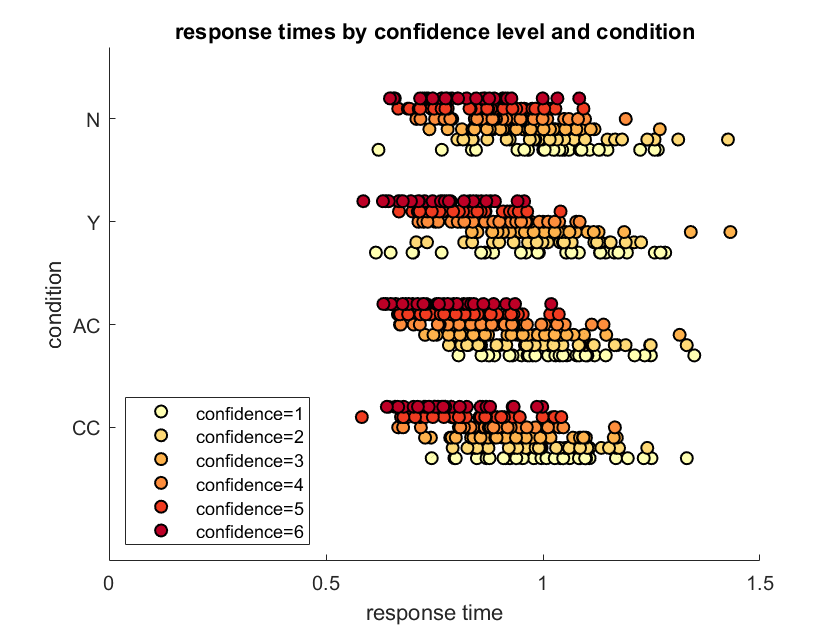

h = figure; hold on;
load('confcb.mat')

for i_r = 1:6
    meanRT_C = [];
    meanRT_A = [];
    meanRT_Y = [];
    meanRT_N = [];

    for s = 1:length(subjects)
    
        subject = data_struct(subjects{s});
        RT_C = subject.DisRT(subject.DisResp==1 & subject.DisConf ==i_r & included_trials(s,:)');
        RT_A = subject.DisRT(subject.DisResp==0 & subject.DisConf ==i_r & included_trials(s,:)');
        RT_Y = subject.DetRT(subject.DetResp==1 & subject.DetConf ==i_r & included_trials(s,:)');
        RT_N = subject.DetRT(subject.DetResp==0 & subject.DetConf ==i_r & included_trials(s,:)');
        
        meanRT_C(s) = nanmean(RT_C);
        meanRT_A(s) = nanmean(RT_A);
        meanRT_Y(s) = nanmean(RT_Y);
        meanRT_N(s) = nanmean(RT_N);
    
        
    end
    
    
    scatter([(10+i_r-1)*ones(35,1); (20+i_r-1)*ones(35,1); (30+i_r-1)*ones(35,1); (40+i_r-1)*ones(35,1)],...
        [meanRT_C meanRT_A meanRT_Y, meanRT_N],[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(i_r,:),'LineWidth',1);
%     scatter((20+i_r-1)*ones(33,1),meanRT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(3,:),'LineWidth',1);
%     scatter((33+i_r-1)*ones(33,1),meanRT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(5,:),'LineWidth',1);
%     scatter((40+i_r-1)*ones(33,1),meanRT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(4,:),'LineWidth',1);
    
    
%     frame = getframe(h); 
%       im = frame2im(frame); 
%       [imind,cm] = rgb2ind(im,256); 
%       % Write to the GIF File 
%       if i_r == 1 
%           imwrite(imind,cm,'RTbyconf.gif','gif', 'Loopcount',inf); 
%       else 
%           imwrite(imind,cm,'RTbyconf.gif','gif','WriteMode','append'); 
%       end 
end
ylabel('response time');
    xlim([0,50]); xlabel('condition'); ylim([0,1.5]);
    title(sprintf('response times by confidence level and condition'));
    set(gca,'xtick',[13:10:50],'xticklabel',{'CC','AC','Y','N'})
    legend('confidence=1', 'confidence=2','confidence=3','confidence=4','confidence=5','confidence=6',...
        'Location','SouthWest')
   

view([90 -90]) 

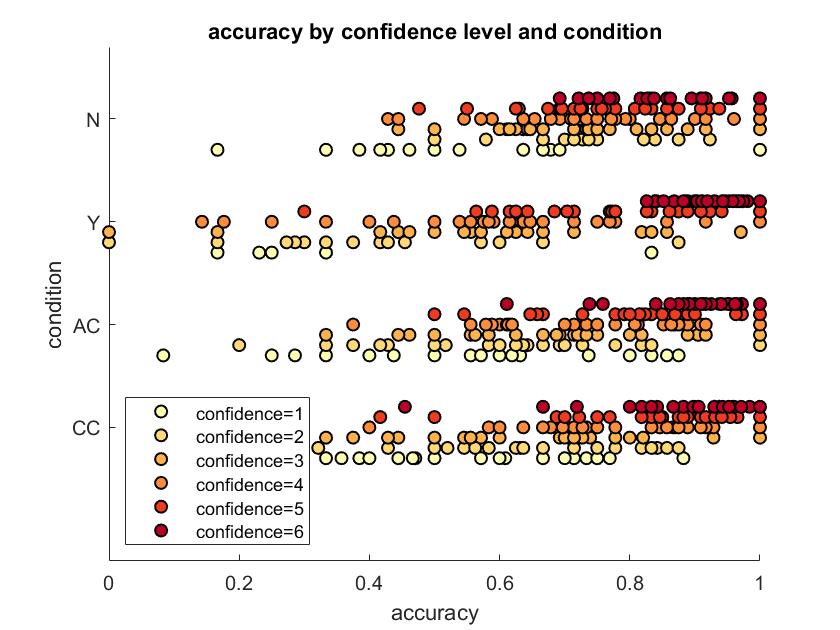


h = figure; hold on;
set(gcf,'color','w');

[meanAcc_C,meanAcc_A,meanAcc_Y,meanAcc_N] = deal([]);
for i_r = 1:6
    
    for s = 1:length(subjects)
    
        subject = data_struct(subjects{s});
        Acc_C = subject.DisCorrect(subject.DisResp==1 & subject.DisConf ==i_r & included_trials(s,:)');
        Acc_A = subject.DisCorrect(subject.DisResp==0 & subject.DisConf ==i_r & included_trials(s,:)');
        Acc_Y = subject.DetCorrect(subject.DetResp==1 & subject.DetConf ==i_r & included_trials(s,:)');
        Acc_N = subject.DetCorrect(subject.DetResp==0 & subject.DetConf ==i_r & included_trials(s,:)');
        
        if numel(Acc_C)>5
            meanAcc_C(s,i_r) = nanmean(Acc_C);
        else
            meanAcc_C(s,i_r) = nan;
        end
        
        if numel(Acc_A)>5
            meanAcc_A(s,i_r) = nanmean(Acc_A);
        else
            meanAcc_A(s,i_r) = nan;
        end
        
        if numel(Acc_Y)>5
            meanAcc_Y(s,i_r) = nanmean(Acc_Y);
        else
            meanAcc_Y(s,i_r) = nan;
        end
        
        if numel(Acc_N)>5
            meanAcc_N(s,i_r) = nanmean(Acc_N);
        else
            meanAcc_N(s,i_r) = nan;
        end
    end
    
    
    scatter([(10+i_r-1)*ones(35,1); (20+i_r-1)*ones(35,1); (30+i_r-1)*ones(35,1); (40+i_r-1)*ones(35,1)],...
        [meanAcc_C(:,i_r); meanAcc_A(:,i_r); meanAcc_Y(:,i_r); meanAcc_N(:,i_r)],[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(i_r,:),'LineWidth',1);
%     scatter((20+i_r-1)*ones(33,1),meanRT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(3,:),'LineWidth',1);
%     scatter((33+i_r-1)*ones(33,1),meanRT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(5,:),'LineWidth',1);
%     scatter((40+i_r-1)*ones(33,1),meanRT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',confcb(4,:),'LineWidth',1);
    
    
%     frame = getframe(h); 
%       im = frame2im(frame); 
%       [imind,cm] = rgb2ind(im,256); 
%       % Write to the GIF File 
%       if i_r == 1 
%           imwrite(imind,cm,'RTbyconf.gif','gif', 'Loopcount',inf); 
%       else 
%           imwrite(imind,cm,'RTbyconf.gif','gif','WriteMode','append'); 
%       end 
end
ylabel('accuracy');
    xlim([0,50]); xlabel('condition'); ylim([0,1]);
    title(sprintf('accuracy by confidence level and condition'));
    set(gca,'xtick',[13:10:50],'xticklabel',{'CC','AC','Y','N'})
    legend('confidence=1', 'confidence=2','confidence=3','confidence=4','confidence=5','confidence=6',...
        'Location','SouthWest')

view([90 -90])    

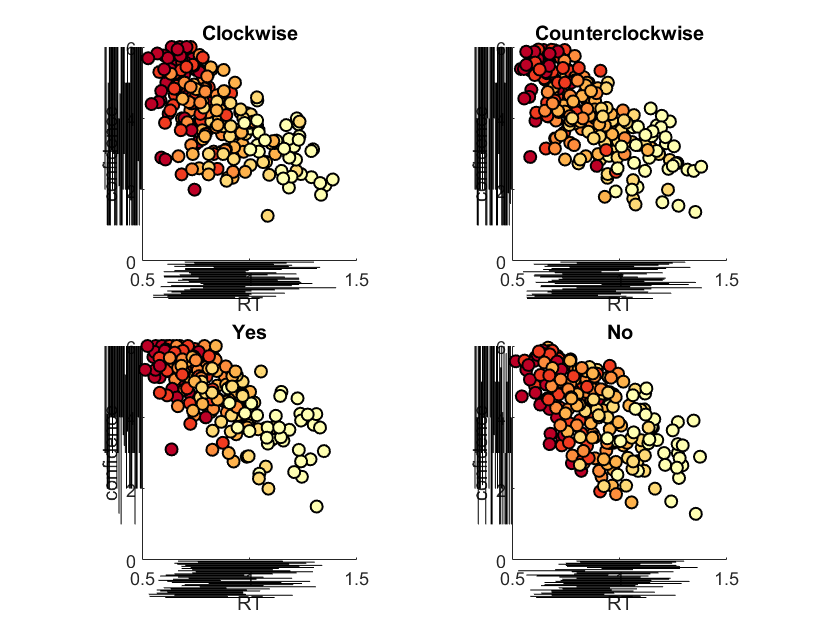

h = figure; hold on;
set(gcf,'color','w');
ax_C = subplot(2,2,1); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Clockwise');
    ylim([0,6]); xlim([0.5,1.5]); ax_C.Clipping = 'off';
ax_A = subplot(2,2,2); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Counterclockwise');
    ylim([0,6]); xlim([0.5,1.5]); ax_A.Clipping = 'off';
ax_Y = subplot(2,2,3); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('Yes');
    ylim([0,6]); xlim([0.5,1.5]); ax_Y.Clipping = 'off';
ax_N = subplot(2,2,4); hold on;  pbaspect([1 1 1]);...
    ylabel('confidence'); xlabel('RT'); title('No');
    ylim([0,6]); xlim([0.5,1.5]); ax_N.Clipping = 'off';

[RT_C_hist, RT_A_hist,RT_Y_hist,RT_N_hist,...
    conf_C_hist,conf_A_hist,conf_Y_hist,conf_N_hist] = deal([]);


    for s = 1:length(subjects)
    
        subject = data_struct(subjects{s});
        [RT_C, C_idx] = sort(subject.DisRT(subject.DisResp==1  & included_trials(s,:)'));
        [RT_A, A_idx] = sort(subject.DisRT(subject.DisResp==0  & included_trials(s,:)'));
        [RT_Y, Y_idx] = sort(subject.DetRT(subject.DetResp==1  & included_trials(s,:)'));
        [RT_N, N_idx] = sort(subject.DetRT(subject.DetResp==0  & included_trials(s,:)'));
        
        conf_C = subject.DisConf(subject.DisResp==1  & included_trials(s,:)');
        conf_C = conf_C(C_idx);
        conf_A = subject.DisConf(subject.DisResp==0  & included_trials(s,:)');
        conf_A = conf_A(A_idx);
        conf_Y = subject.DetConf(subject.DetResp==1  & included_trials(s,:)');
        conf_Y = conf_Y(Y_idx);
        conf_N = subject.DetConf(subject.DetResp==0  & included_trials(s,:)');
        conf_N = conf_N(N_idx);
        
        C_bin_size = floor(length(conf_C)/6);
        C_boundaries = [1,C_bin_size*[1:5],length(conf_C)];
        
        A_bin_size = floor(length(conf_A)/6);
        A_boundaries = [1,A_bin_size*[1:5],length(conf_A)];
        
        Y_bin_size = floor(length(conf_Y)/6);
        Y_boundaries = [1,Y_bin_size*[1:5],length(conf_Y)];
        
        N_bin_size = floor(length(conf_N)/6);
        N_boundaries = [1,N_bin_size*[1:5],length(conf_N)];
        
        for i_b = 1:6
            RT_C_hist(s,i_b) = mean(RT_C(C_boundaries(i_b):C_boundaries(i_b+1)));
            RT_A_hist(s,i_b) = mean(RT_A(A_boundaries(i_b):A_boundaries(i_b+1)));
            RT_Y_hist(s,i_b) = mean(RT_Y(Y_boundaries(i_b):Y_boundaries(i_b+1)));
            RT_N_hist(s,i_b) = mean(RT_N(N_boundaries(i_b):N_boundaries(i_b+1)));
            
            conf_C_hist(s,i_b) = mean(conf_C(C_boundaries(i_b):C_boundaries(i_b+1)));
            conf_A_hist(s,i_b) = mean(conf_A(A_boundaries(i_b):A_boundaries(i_b+1)));
            conf_Y_hist(s,i_b) = mean(conf_Y(Y_boundaries(i_b):Y_boundaries(i_b+1)));
            conf_N_hist(s,i_b) = mean(conf_N(N_boundaries(i_b):N_boundaries(i_b+1)));
            
          scatter(RT_C_hist(s,i_b), conf_C_hist(s,i_b),...
          [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
          'Parent',ax_C);
                
          scatter(RT_A_hist(s,i_b), conf_A_hist(s,i_b),...
          [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
          'Parent',ax_A);
      
          scatter(RT_Y_hist(s,i_b), conf_Y_hist(s,i_b),...
          [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
          'Parent',ax_Y); 
      
          scatter(RT_N_hist(s,i_b), conf_N_hist(s,i_b),...
          [],'MarkerEdgeColor','k','MarkerFaceColor',confcb(7-i_b,:),'LineWidth',1,...
          'Parent',ax_N);        
        end
        plot(ax_C, prctile(RT_C, [10,90]),-0.03*s*[1,1],'-k')
        plot(ax_C,0.5-0.005*s*[1,1], prctile(conf_C, [10,90]),'-k')
        
        plot(ax_A, prctile(RT_A, [10,90]),-0.03*s*[1,1],'-k')
        plot(ax_A,0.5-0.005*s*[1,1], prctile(conf_A, [10,90]),'-k')
        
        plot(ax_Y, prctile(RT_Y, [10,90]),-0.03*s*[1,1],'-k')
        plot(ax_Y,0.5-0.005*s*[1,1], prctile(conf_Y, [10,90]),'-k')
        
        plot(ax_N, prctile(RT_N, [10,90]),-0.03*s*[1,1],'-k')
        plot(ax_N,0.5-0.005*s*[1,1], prctile(conf_N, [10,90]),'-k')
        
    end

## 5. confidence

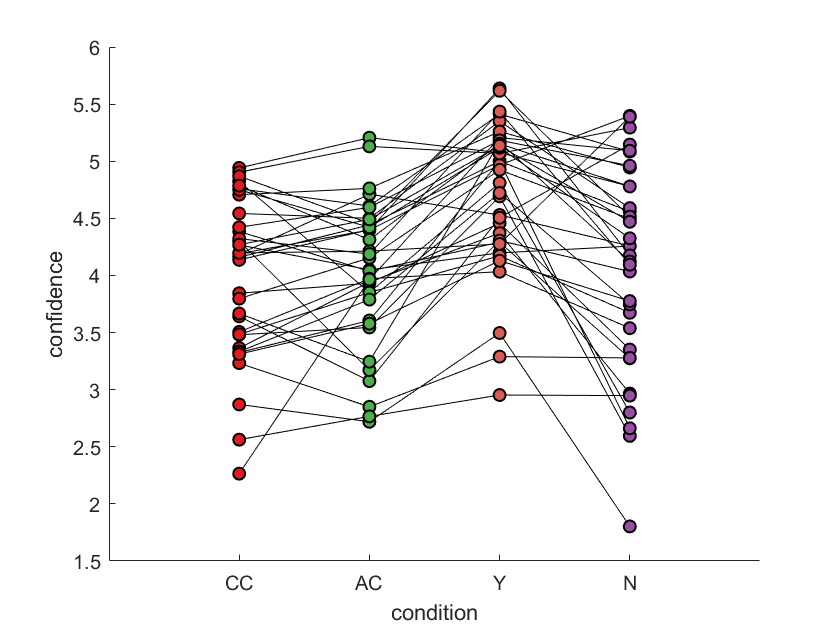

conf_C = [];
conf_A = [];
conf_Y = [];
conf_N = [];

hist_C = [];
hist_A = [];
hist_Y = [];
hist_N = [];

hist_CC = [];
hist_AA = [];
hist_YY = [];
hist_NN = [];

hist_CA = [];
hist_AC = [];
hist_YN = [];
hist_NY = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    
    conf_C(s) = nanmean(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'));
    conf_A(s) = nanmean(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'));
    conf_Y(s) = nanmean(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'));
    conf_N(s) = nanmean(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'));
    
    hist_C(s,:) = hist(subject.DisConf(subject.DisResp==1 & included_trials(s,:)'),1:6);
    hist_A(s,:) = hist(subject.DisConf(subject.DisResp==0 & included_trials(s,:)'),1:6);
    hist_Y(s,:) = hist(subject.DetConf(subject.DetResp==1 & included_trials(s,:)'),1:6);
    hist_N(s,:) = hist(subject.DetConf(subject.DetResp==0 & included_trials(s,:)'),1:6);
    
   
    hist_CC(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_AA(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_YY(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    hist_NN(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 1 & included_trials(s,:)'),1:6);
    
    hist_CA(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_AC(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_YN(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);
    hist_NY(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DisCorrect == 0 & included_trials(s,:)'),1:6);

end

hist_mat = [mean(hist_C); mean(hist_A); mean(hist_Y); mean(hist_N)];

figure; hold on;
plot([conf_C;conf_A;conf_Y;conf_N],'k');
scatter(ones(35,1),conf_C,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(2*ones(35,1),conf_A,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(3*ones(35,1),conf_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(5,:),'LineWidth',1);
scatter(4*ones(35,1),conf_N,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
ylabel('confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'CC','AC','Y','N'})

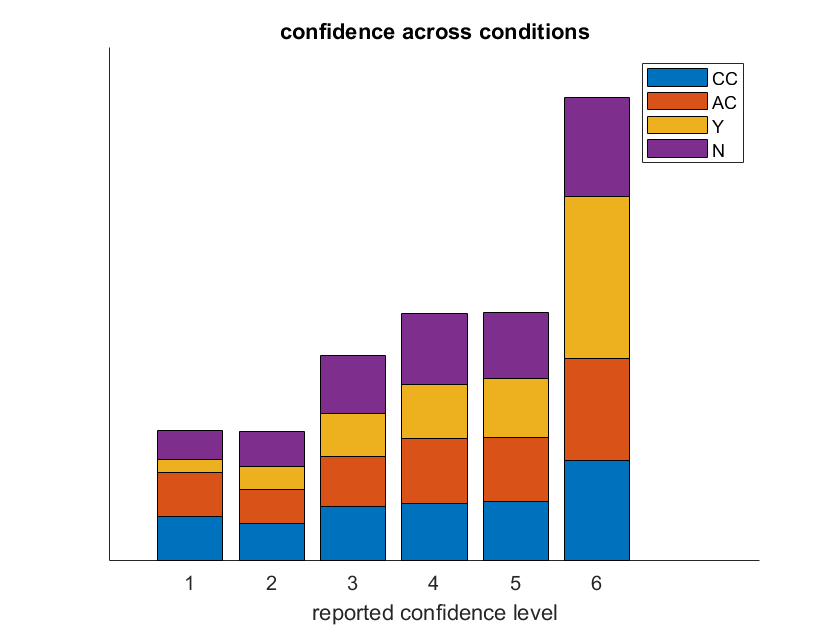

%stacked histogram
figure; hold on;
title('confidence across conditions')
bar(hist_mat','stacked');
colormap(cb([1,3,5,4],:));
xlim([0,8]);set(gca,'xtick',[1:6]) 
xlabel('reported confidence level'); set(gca, 'ytick',[]);
legend('CC','AC','Y','N')

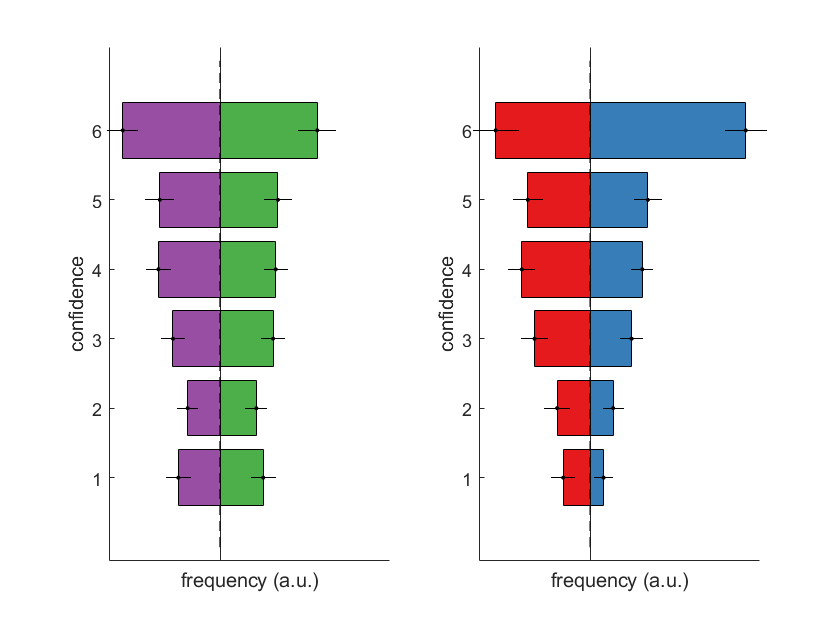


%symmetric bar charts
figure; 
ax1=subplot(1,2,1);
hold on;
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
ylabel('frequency (a.u.)');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
xlabel('confidence')
view([90,-90])
% legend([c_bar,a_bar],{'clockwise','anticlockwise'}, 'Location','Northwest')
ax2=subplot(1,2,2);
hold on;
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
view([90 -90]) 
% legend([y_bar,n_bar],{'yes','no'}, 'Location','Northwest')
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence'); ylabel('frequency (a.u.)');
fig = gcf;
linkaxes([ax1,ax2],'y')


s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 20;
s.Height = 10;
% hgexport(fig,'figures/confidenceDistributions',s);

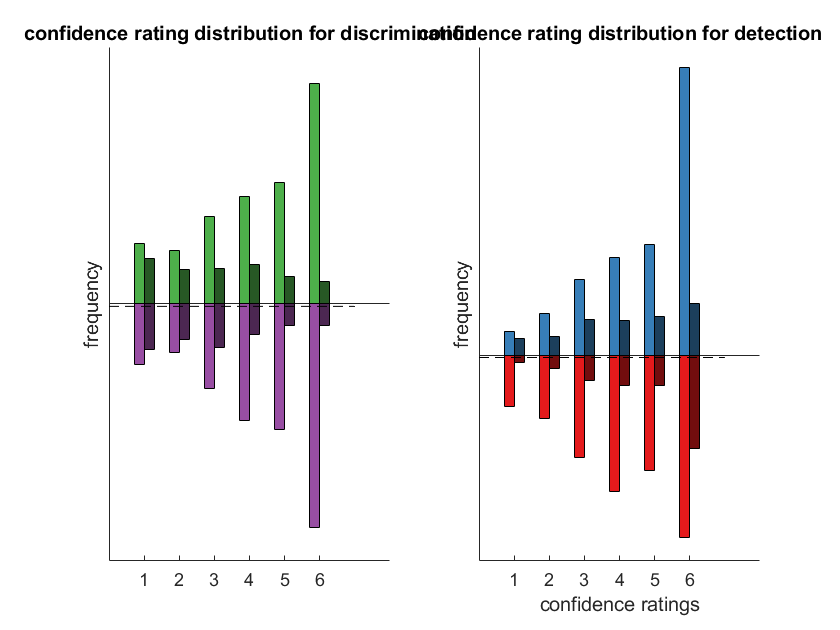


%symmetric bar charts
figure; 
subplot(1,2,1);
hold on;
title('confidence rating distribution for discrimination');

c_bar = bar([mean(hist_CC); mean(hist_AC)]','BarWidth',1);
c_bar(1).FaceColor=cb(3,:);
c_bar(2).FaceColor=cb(3,:)/2;

a_bar = bar([-mean(hist_AA); -mean(hist_CA)]','BarWidth',1);
a_bar(1).FaceColor=cb(4,:);
a_bar(2).FaceColor=cb(4,:)/2;

% errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
ylabel('frequency');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');

subplot(1,2,2);
hold on;
title('confidence rating distribution for detection');

y_bar = bar([mean(hist_YY); mean(hist_NY)]','BarWidth',1);
y_bar(1).FaceColor=cb(2,:);
y_bar(2).FaceColor=cb(2,:)/2;

n_bar = bar([-mean(hist_NN); -mean(hist_YN)]','BarWidth',1);
n_bar(1).FaceColor=cb(1,:);
n_bar(2).FaceColor=cb(1,:)/2;

plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');

set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');


fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 6.7*0.8 4/3];
% print('figures/distributions_byacc','-dpng','-r600');
% print('figures/distributions_byacc_300dpi','-dpng','-r300');
    
sprintf('There is a correlation of %.04f between the attenuation effect and the mean confidence effect',...
    corr(conf_Y'-conf_N',cor_Y'-cor_N'))

ans = 'There is a correlation of -0.3680 between the attenuation effect and the mean confidence effect'

## 3. Response Bias

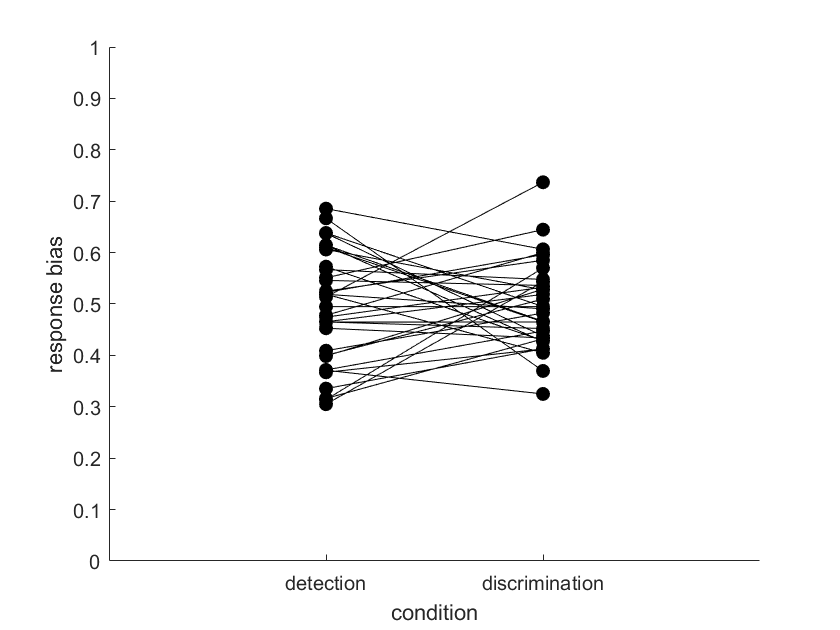


meanRespDet = [];
meanRespDis = [];

for s = 1:length(subjects)

    subject = data_struct(subjects{s});
    
    meanRespDet(s) = nanmean(subject.DetResp(included_trials(s,:)'>0));
    meanRespDis(s) = nanmean(subject.DisResp(included_trials(s,:)'>0));

end

figure; hold on;
plot([meanRespDet;meanRespDis],'k');
scatter(ones(35,1),meanRespDet,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
scatter(2*ones(35,1),meanRespDis,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
ylabel('response bias'); ylim([0,1])
xlim([0,3]); xlabel('condition');
set(gca,'xtick',[1:2],'xticklabel',{'detection','discrimination'})

## 4. Confidence

For confidence related analyses, we exclude runs in which a particular answer was accompanied by the same confidence rating in 95% of the trials.

I couldn't think of a good way to represent confidence ratings, so I went with a stacked bar plot. 

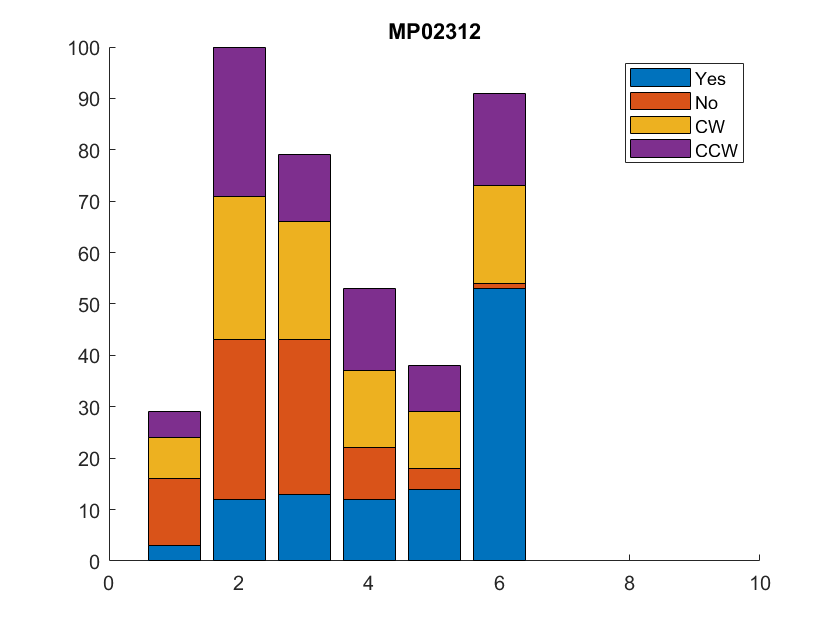

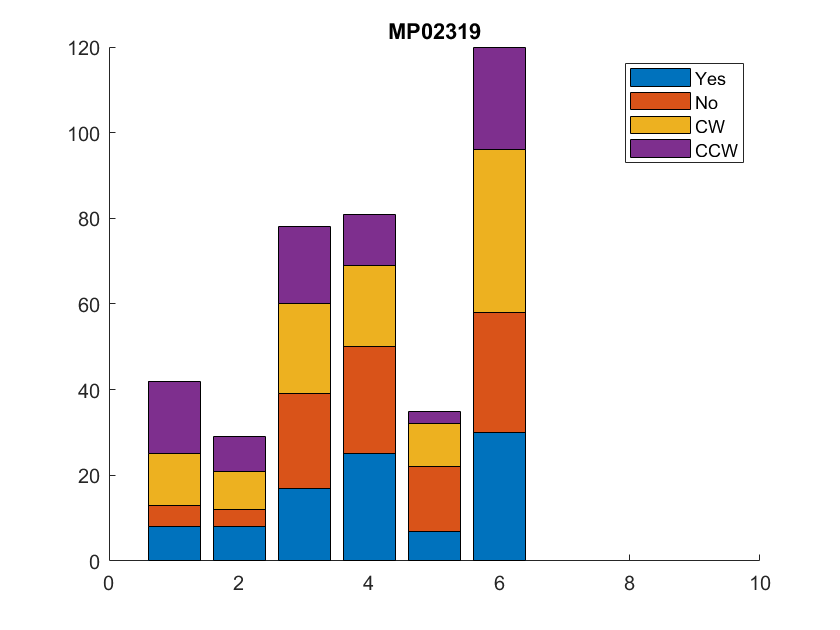

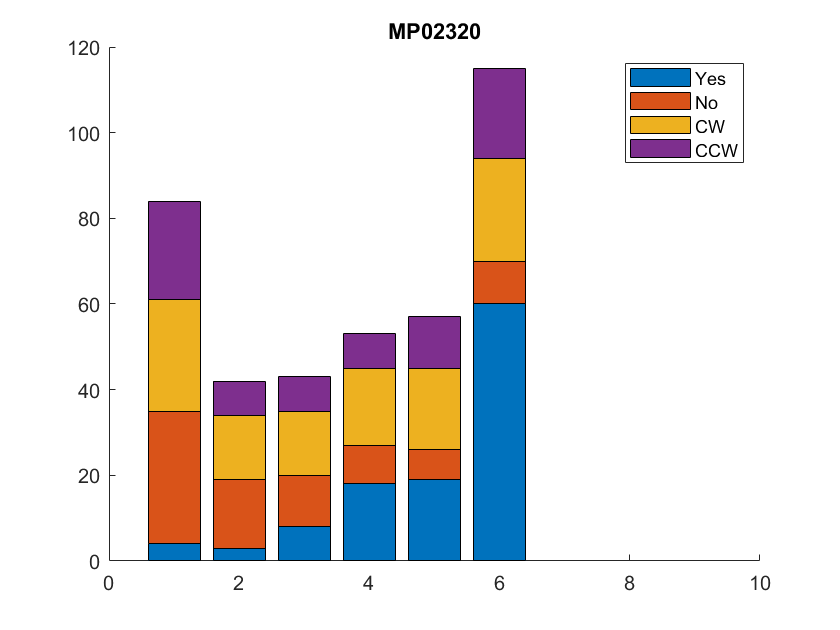

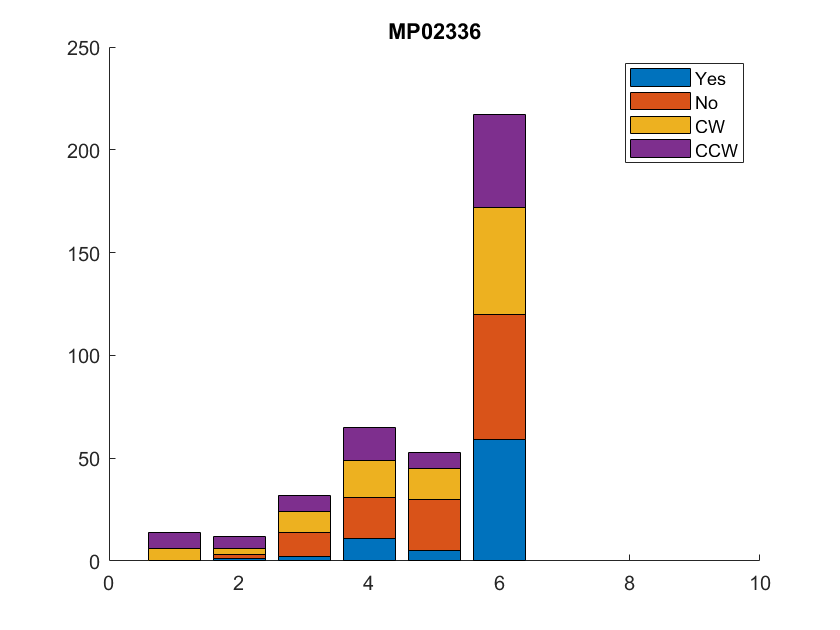

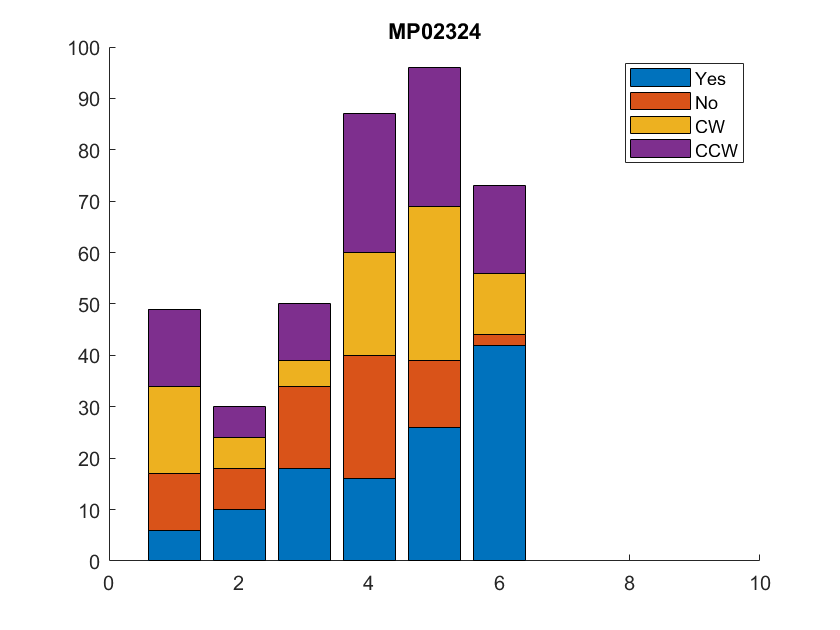

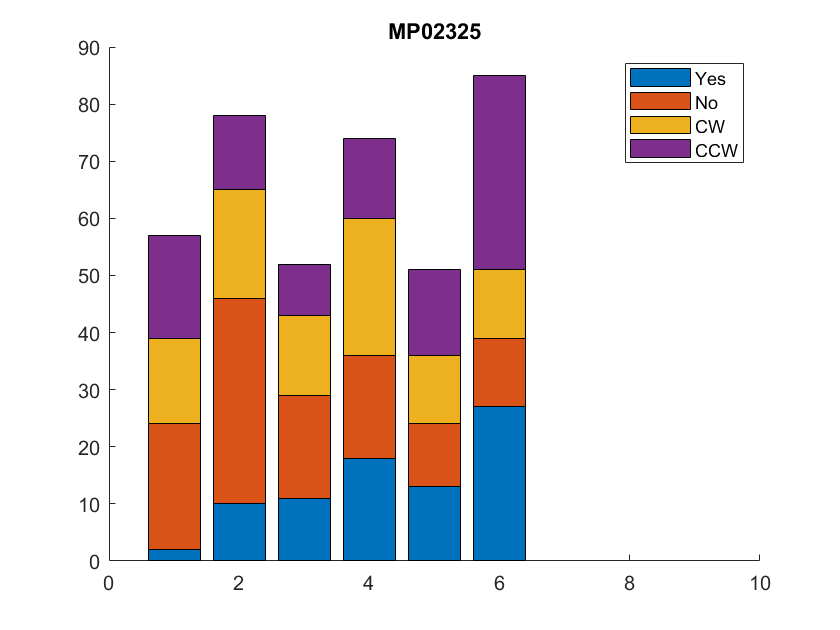

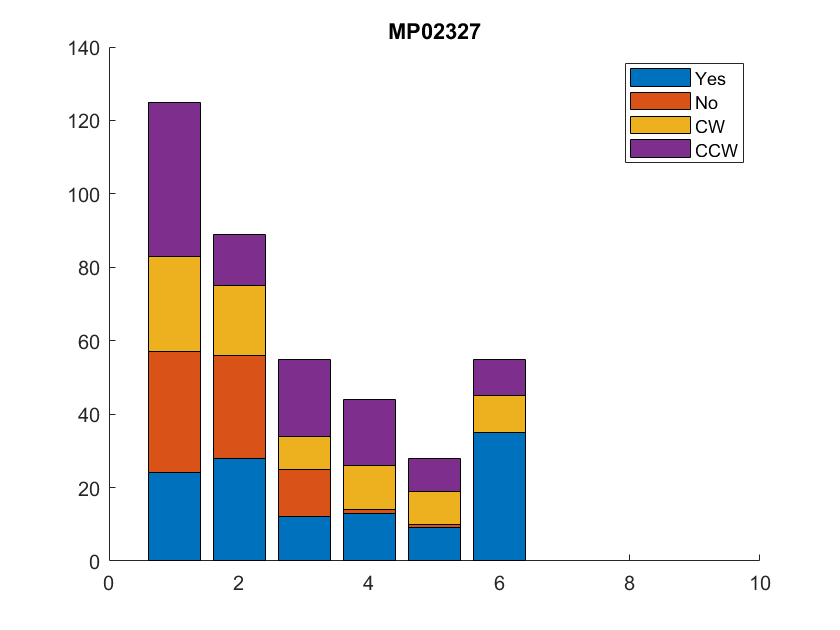

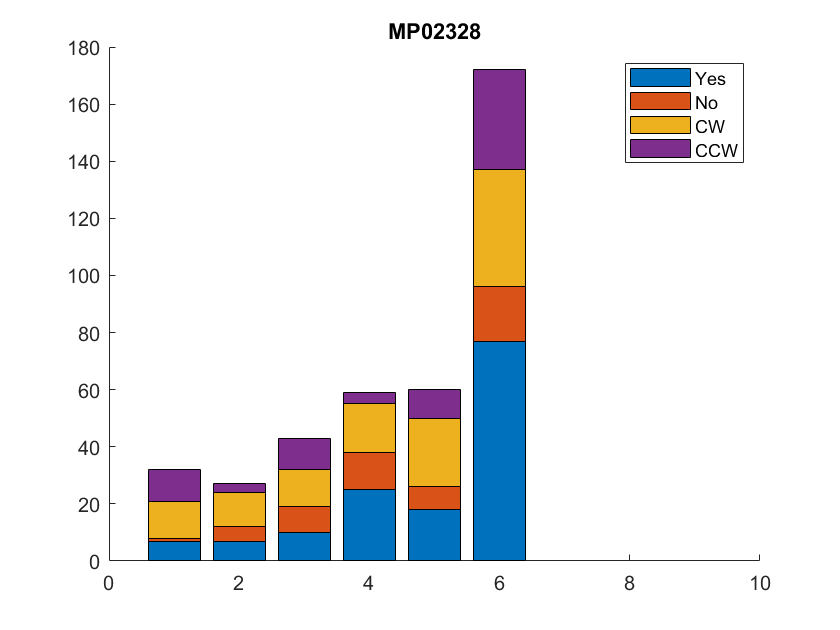

Run 3 of participant MP02333 was excluded from confidence analysis 



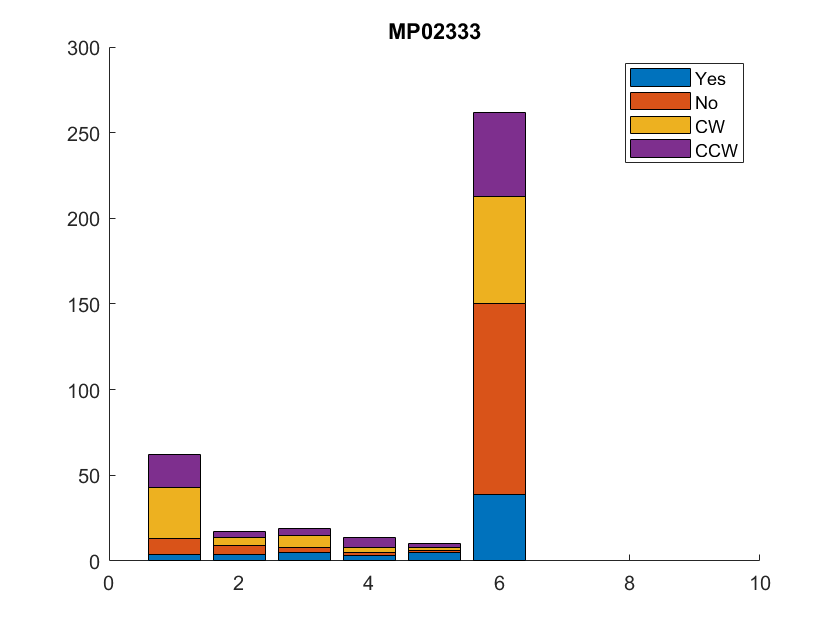

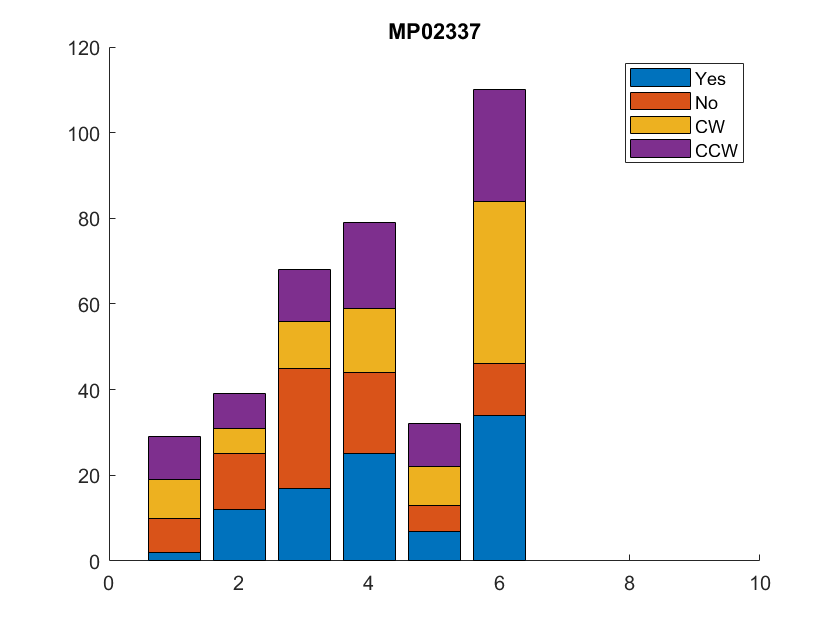

Run 1 of participant MP02417 was excluded from confidence analysis 



totalConfidenceExclusions = [0,0];    

for s = 1:length(subjects)
    
   
    subject = data_struct(subjects{s});

    
    for run_num = 1:length(subject.DisRT)/40
        
%         figure;
%         title(sprintf('%s: run number %d', subjects{s}, run_num))
%         hold on;
        range = (run_num-1)*40+1:run_num*40;
        conf_matrix = [hist(subject.DetConf(subject.DetResp(range)==1),1:6);... %yes responses
                        hist(subject.DetConf(subject.DetResp(range)==0),1:6);... %no responses
                        hist(subject.DisConf(subject.DisResp(range)==1),1:6);... %CW responses
                        hist(subject.DisConf(subject.DisResp(range)==0),1:6)];    %CCW responses
                    
%         bar(conf_matrix','stacked');
%         xlim([0,10]);
%         legend('Yes','No','CW','CCW')
        
        %check if confidence ratings meet the exclusion criterion
        normalized_conf_matrix = conf_matrix./(repmat(sum(conf_matrix,2),1,6));
        if any(normalized_conf_matrix(:)>0.95) && toExclude(s,run_num)==0
            toExclude(s,run_num)=0.5;
            disp(sprintf('Run %d of participant %s was excluded from confidence analysis \n',run_num, subjects{s}))
            disp(repmat('=',1,60))
            totalConfidenceExclusions(2) = totalConfidenceExclusions(2)+1;
        end
    end
  
    %plot global confidence distribution
    conf_matrix = [hist(subject.DetConf(subject.DetResp==1),1:6);... %yes responses
                        hist(subject.DetConf(subject.DetResp==0),1:6);... %no responses
                        hist(subject.DisConf(subject.DisResp==1),1:6);... %CW responses
                        hist(subject.DisConf(subject.DisResp==0),1:6)];    %CCW responses
    figure;
    hold on
    title(subjects{s})
    bar(conf_matrix','stacked');
    xlim([0,10]);
    legend('Yes','No','CW','CCW')
    
end

## 5. Response Conditional ROCs

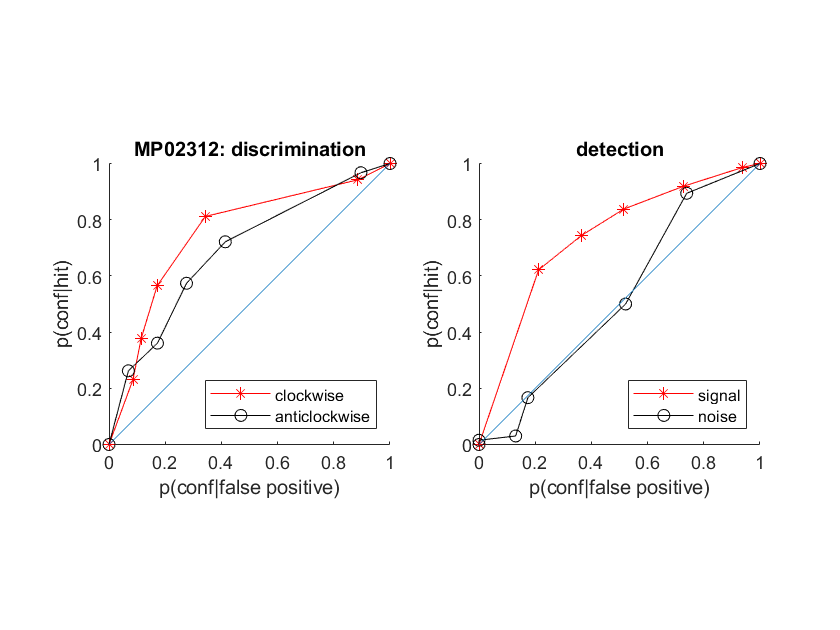

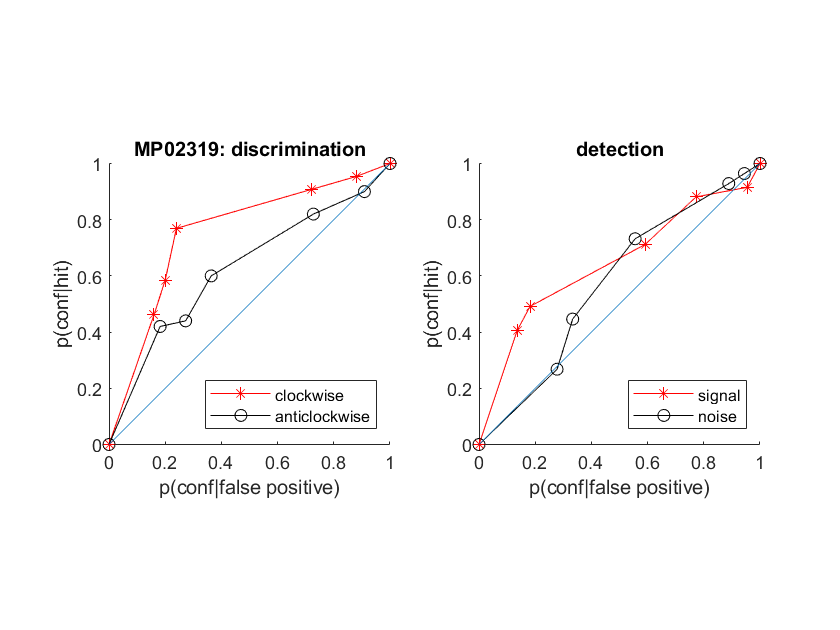

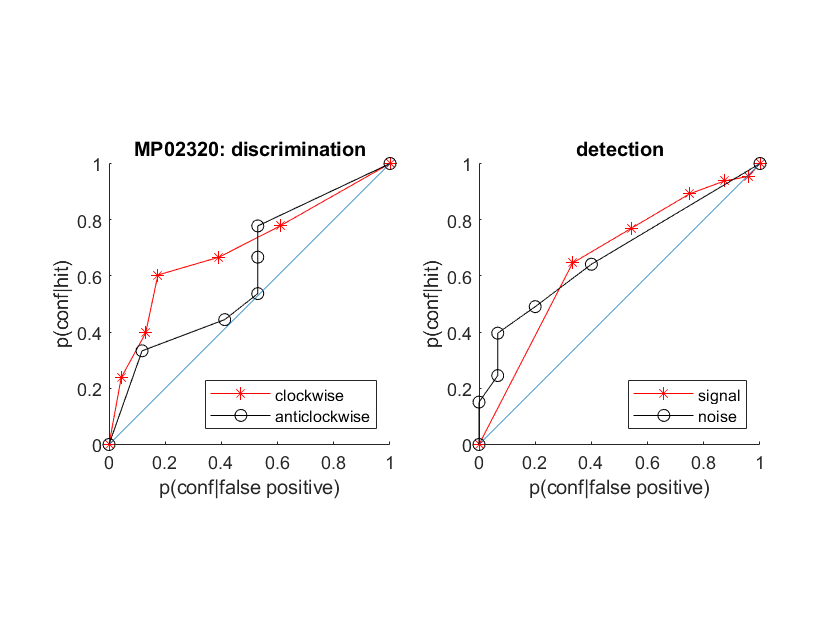

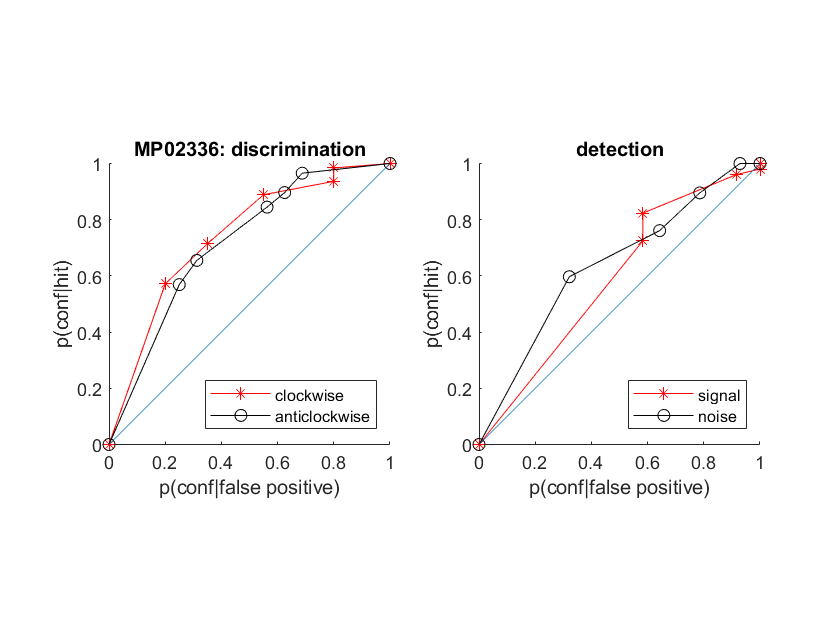

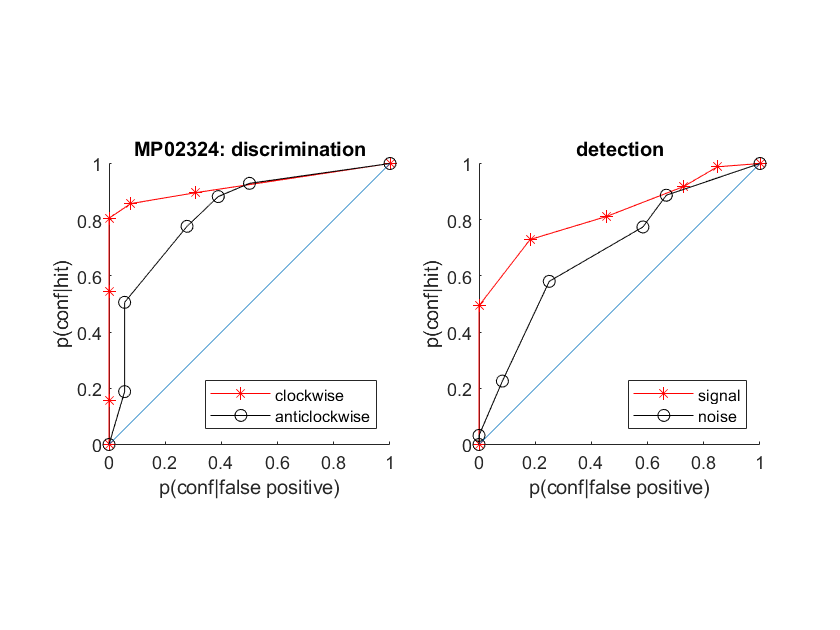

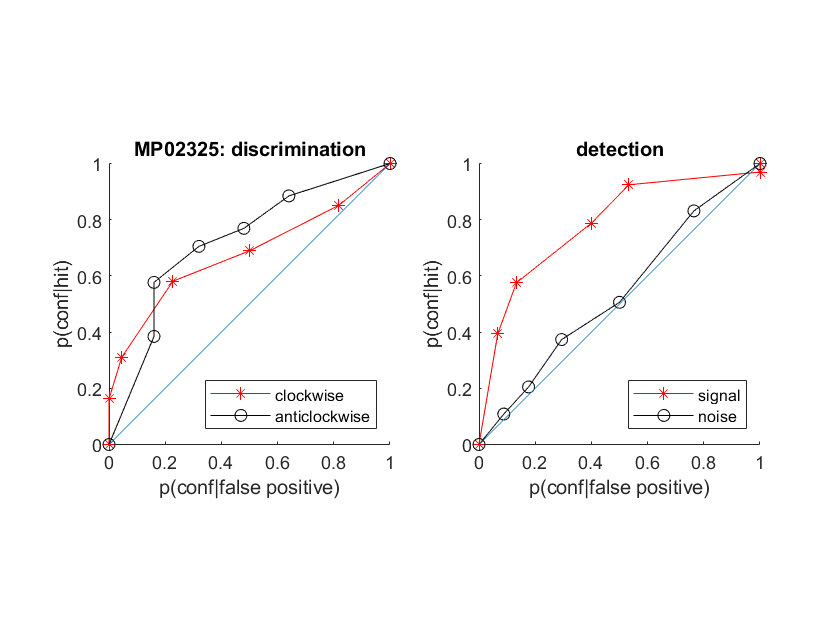

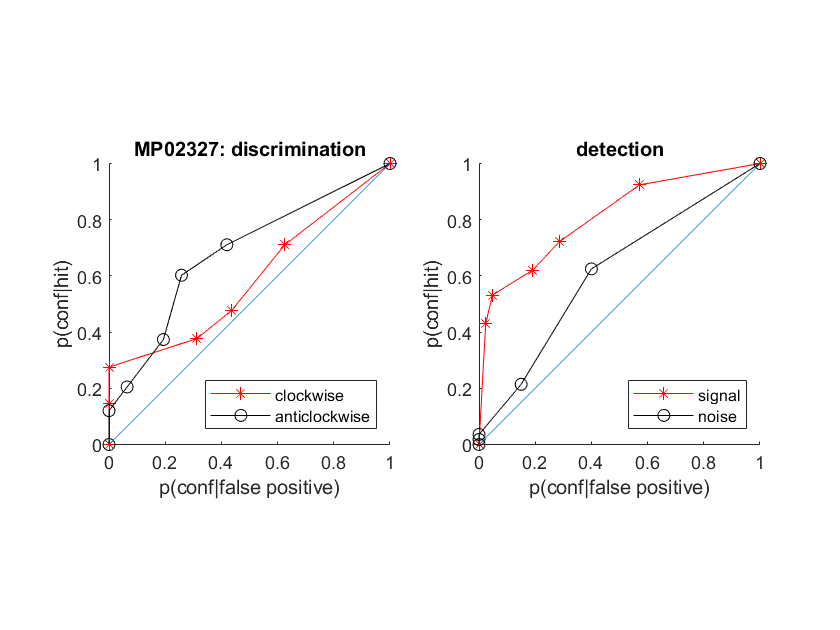

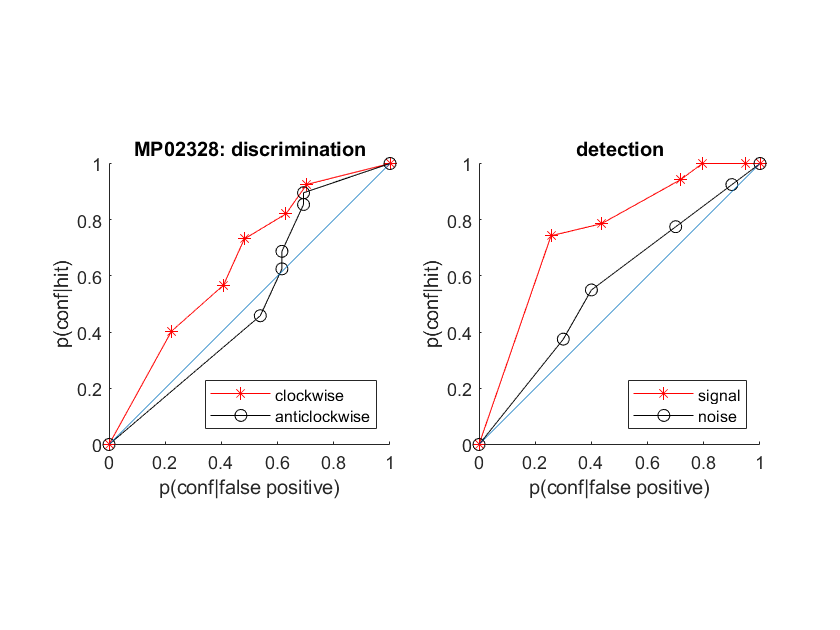

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);
[nR_S1,nR_S2,nR_signal_nR_noise] = deal([]);

for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);

    
    %break into taskXresponseXsignal
    DisCC = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1 & included_trials(s,:)'),1:6);
    DisCA = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0 & included_trials(s,:)'),1:6);
    DisAC = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1 & included_trials(s,:)'),1:6);
    DisAA = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0 & included_trials(s,:)'),1:6);
    DetSignalYes = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1 & included_trials(s,:)'),1:6);
    DetSignalNo = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0 & included_trials(s,:)'),1:6);
    DetNoiseYes = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1 & included_trials(s,:)'),1:6);
    DetNoiseNo = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0 & included_trials(s,:)'),1:6);
    
    nR_S1(s,:) = [reshape(DisAA(end:-1:1),1,[]) reshape(DisAC,1,[])];
    nR_S2(s,:) = [reshape(DisCA(end:-1:1),1,[]) reshape(DisCC,1,[])];
    nR_signal(s,:) = [reshape(DetSignalNo(end:-1:1),1,[]) reshape(DetSignalYes,1,[])];
    nR_noise(s,:) = [reshape(DetNoiseNo(end:-1:1),1,[]) reshape(DetNoiseYes,1,[])];
    
    %% plot discrimination
    figure;
    subplot(1,2,1);
    hold on;
    axis equal
    
    %up responses
    plot([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
        [0; cumsum(DisCC(end:-1:1))/sum(DisCC)], '-*r');
    upAUC(s) = trapz([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
        [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]);
    
    ACGroup = [ACGroup [0; cumsum(DisAC(end:-1:1))/sum(DisAC)]];
    CCGroup = [CCGroup [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]];

    %down responses
    plot([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
        [0; cumsum(DisAA(end:-1:1))/sum(DisAA)], '-ok');
    downAUC(s) = trapz([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
        [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]);
    
    AAGroup = [AAGroup [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]];
    CAGroup = [CAGroup [0; cumsum(DisCA(end:-1:1))/sum(DisCA)]];
    
    xlabel('p(conf|false positive)');
    ylabel('p(conf|hit)');
    title([subjects{s}, ': discrimination']);
    set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
    set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
    refline(1,0);
    legend('clockwise', 'anticlockwise', 'Location', 'southeast')
    
    %% plot detection
    if sum(subject.DetSignal==0 & subject.DetResp==1)>1
        subplot(1,2,2);
        hold on;
        axis equal
        
        %yes responses
        plot([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
            [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)], '-*r');
        
        yesAUC(s) = trapz([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
            [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]);
        
        NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
        SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
        
        %no responses
        plot([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
            [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)],'-ok');
       noAUC(s) = trapz([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
            [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]);
    
        NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
        SignalNoGroup = [SignalNoGroup [0;
            cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
        
        xlabel('p(conf|false positive)');
        ylabel('p(conf|hit)');
        title('detection');
        set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
        set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
        refline(1,0);
        legend('signal', 'noise', 'Location', 'southeast')
    end
end

set(0,'defaultAxesFontSize',10)
figure;
ax1=subplot(3,4,[1,2,5,6]);
% ax1=subplot(1,2,1);
hold on;
axis equal
 %up responses
refline(1,0);

errorbar(mean(ACGroup,2),mean(CCGroup,2),std(ACGroup')/sqrt(35),std(ACGroup')/sqrt(35),...
    std(CCGroup')/sqrt(35),std(CCGroup')/sqrt(35),'k')
c=plot(mean(ACGroup,2),mean(CCGroup,2), '-ok', 'MarkerFaceColor',cb(3,:),'MarkerSize',8);
errorbar(mean(CAGroup,2),mean(AAGroup,2),std(CAGroup')/sqrt(35),std(CAGroup')/sqrt(35),...
    std(AAGroup')/sqrt(35),std(AAGroup')/sqrt(35),'k')
a=plot(mean(CAGroup,2),mean(AAGroup,2), '-ok', 'MarkerFaceColor', cb(4,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('discrimination');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([c,a],{sprintf('CLOCKWISE (%.02f)',mean(upAUC)), sprintf('ANTICLOCKWISE (%.02f)',mean(downAUC))}, 'Location', 'southeast')

ax2=subplot(3,4,[3,4,7,8]);
% ax2=subplot(1,2,2);
hold on;
axis equal
refline(1,0);
 %up responses
errorbar(mean(NoiseYesGroup,2),mean(SignalYesGroup,2),std(NoiseYesGroup')/sqrt(35),std(NoiseYesGroup')/sqrt(35),...
    std(SignalYesGroup')/sqrt(35),std(SignalYesGroup')/sqrt(35),'k')
y=plot(mean(NoiseYesGroup,2),mean(SignalYesGroup,2), '-ok', 'MarkerFaceColor',cb(2,:),'MarkerSize',8);
errorbar(mean(SignalNoGroup,2),mean(NoiseNoGroup,2),std(SignalNoGroup')/sqrt(35),std(SignalNoGroup')/sqrt(35),...
    std(NoiseNoGroup')/sqrt(35),std(NoiseNoGroup')/sqrt(35),'k')
n=plot(mean(SignalNoGroup,2),mean(NoiseNoGroup,2), '-ok', 'MarkerFaceColor', cb(1,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('detection');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([y,n],{sprintf('YES (%.02f)',mean(yesAUC)), sprintf('NO (%.02f)', mean(noAUC))}, 'Location', 'southeast')

ax3=subplot(3,4,[9,10]);
hold on;
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
ax4=subplot(3,4,[11,12]);
hold on;
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
linkaxes([ax3,ax4])
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
% ax5 = subplot(3,6,[5,6,11,12,17,18]); hold on;
% 
% % plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
% h=boxplot([meanAccDis;meanAccDet]','Colors','k');
% scatter(ones(35,1)+noise1',meanAccDis,[],'MarkerEdgeColor','k','MarkerFaceColor',...
%     [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
% scatter(2*ones(35,1)+noise2',meanAccDet,[],'MarkerEdgeColor','k','MarkerFaceColor',...
%     [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
% ylabel('mean accuracy');
% xlim([0.5,2.5]); xlabel('task');
% ylim([0.4,1]);
% plot([0.5,2.5],[0.5,0.5],'k--')
% set(gca,'xtick',[1:2],'xticklabel',{'discrimination','detection'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 20;
s.Height = 20;
hgexport(fig,'figures/behaviourCombined',s);

addpath('Maniscalco2011')   
discrimination_M = nan(35,1);
detection_M = nan(35,1);
for i_s = 1:length(subjects)
    dis_fit = fit_meta_d_MLE(nR_S1(i_s,:)+0.1, nR_S2(i_s,:)+0.1);
    discrimination_M(i_s) = dis_fit.M_ratio;
    
    det_fit = fit_meta_d_MLE(nR_noise(i_s,:)+0.1, nR_signal(i_s,:)+0.1);
    detection_M(i_s) = det_fit.M_ratio;
    
end

## Pattern matching

To check if participants were using a specific phase-locked pattern in their 'no' responses, I compute the correlation of each stimulus with the mean of the clockwise and clockwise pure stimuli. I then look only at trials for which this value is negative, and compute the correlation of this value with the confidenceXresponse vector.

If participants used a pattern matching strategy, this value shoud be positive, whereas if they were looking for phase invariant signal it should be negative. The values are generally negative. 

Interestingly, the participant that shows the strongest pattern matching behaviour is 04NiSi, that shows no detection asymmetry and the strongest phsae-invariant matching is 18LuHe, that shows a very strong one with the noise curve lying beneath the diagonal.

% pattern_matching = containers.Map;
% for s = 1:length(subjects)
%     subject = data_struct(subjects{s});
%         pattern_matching(subjects{s}) = corr([subject.DetPatternFit(subject.DetResp==1 & subject.DetPatternFit'<0)';...
%             subject.DetPatternFit(subject.DetResp==0 & subject.DetPatternFit'<0)'],...
%             [subject.DetConf(subject.DetResp==1 & subject.DetPatternFit'<0);...
%             -subject.DetConf(subject.DetResp==0 & subject.DetPatternFit'<0)]);
% end

## Number of button presses as a function of response

detection_presses = nan(35,6);
discrimination_presses = nan(35,6);

for i_s = 1:length(subjects)
    subject = data_struct(subjects{i_s});
    for i_c = 1:6
        detection_presses(i_s,i_c) = nanmean(subject.DetConfInc(included_trials(i_s,:)' & subject.DetConf==i_c)+...
        subject.DetConfDec(included_trials(i_s,:)' & subject.DetConf==i_c)); 
        discrimination_presses(i_s,i_c) = nanmean(subject.DisConfInc(included_trials(i_s,:)' & subject.DisConf==i_c)+...
        subject.DisConfDec(included_trials(i_s,:)' & subject.DisConf==i_c)); 
    end
end

figure; hold on;
a=errorbar(nanmean(detection_presses),nanstd(detection_presses)./sqrt(sum(~isnan(detection_presses))),'-ok');
b=errorbar(nanmean(discrimination_presses),nanstd(discrimination_presses)./sqrt(sum(~isnan(discrimination_presses))),'-xk');
a.MarkerSize = 12;
b.MarkerSize= 12;
xlim([0,7]); xticks(1:6);
ylabel("mean number of presses");
xlabel("confidence");
legend('detection','discrimination','Location','southeast');
fig = gcf;
% s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/conf_presses',s);
